# Part one

fs = 20;
x = @(n) cos(1/fs * 10 *pi.*n + 0.001*pi);
n = -fs:fs-1;
n1 = -fs:fs;

## a

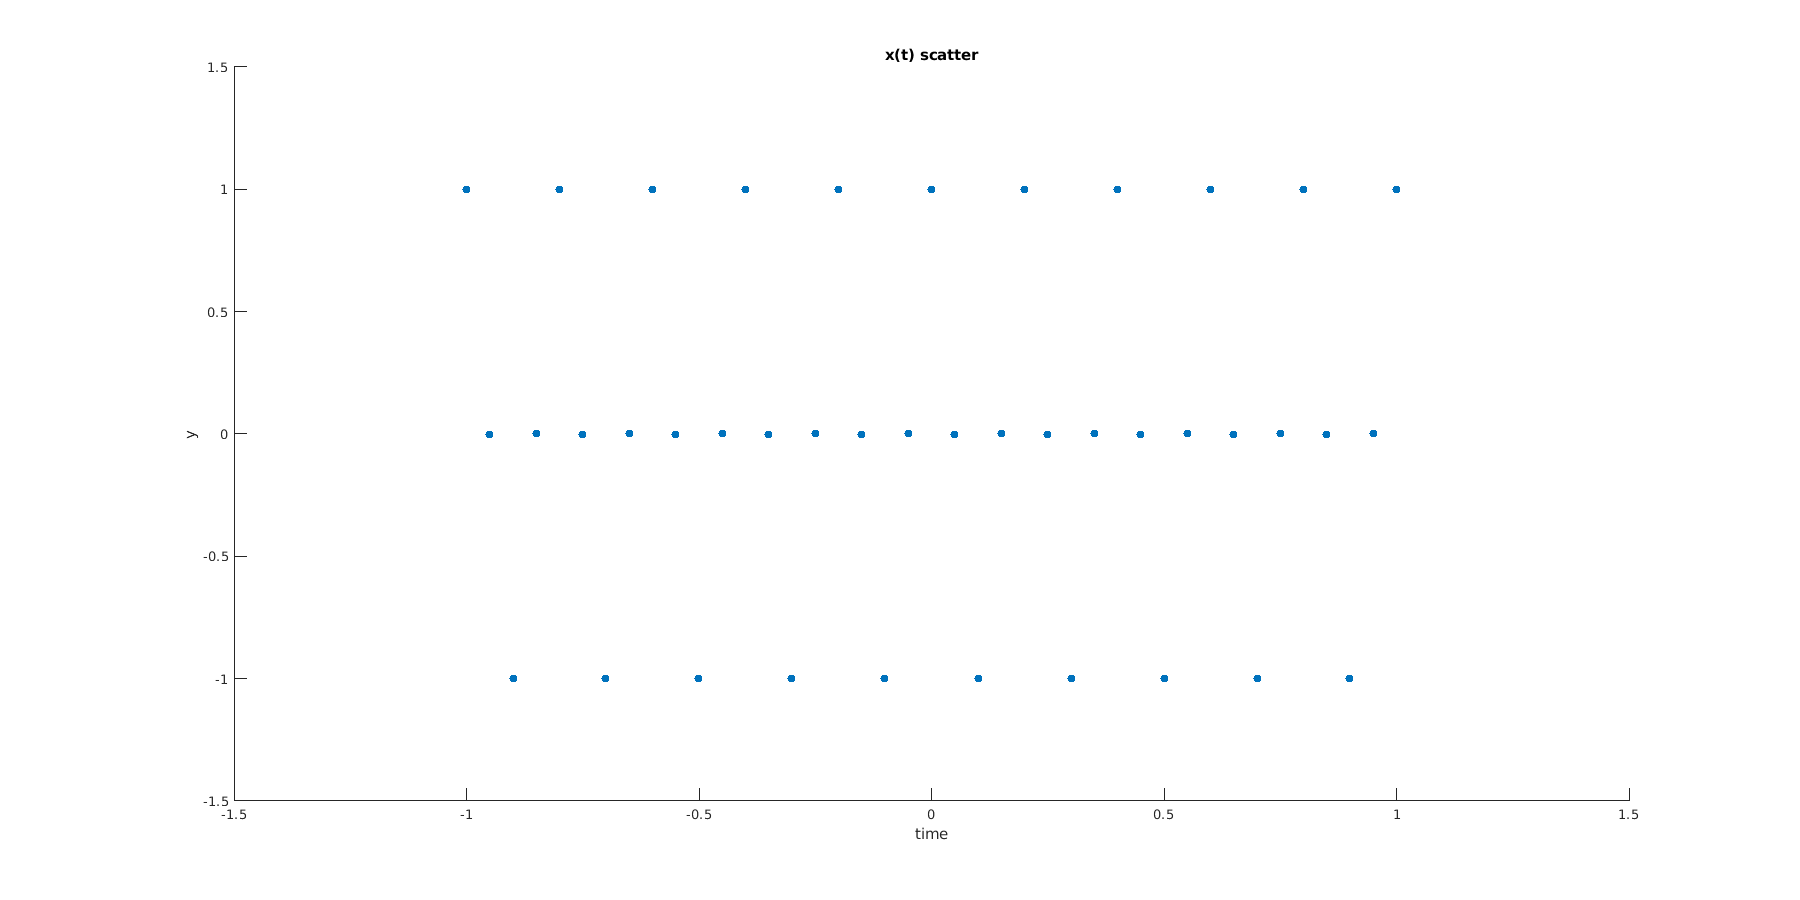

figure;
set(gcf,'position',[0,0,1800,900]);
scatter(n1/fs,x(n1),"filled")
title("x(t) scatter");
xlabel("time");
ylabel("y")
ylim([-1.5,1.5]);
xlim([-1.5,1.5]);

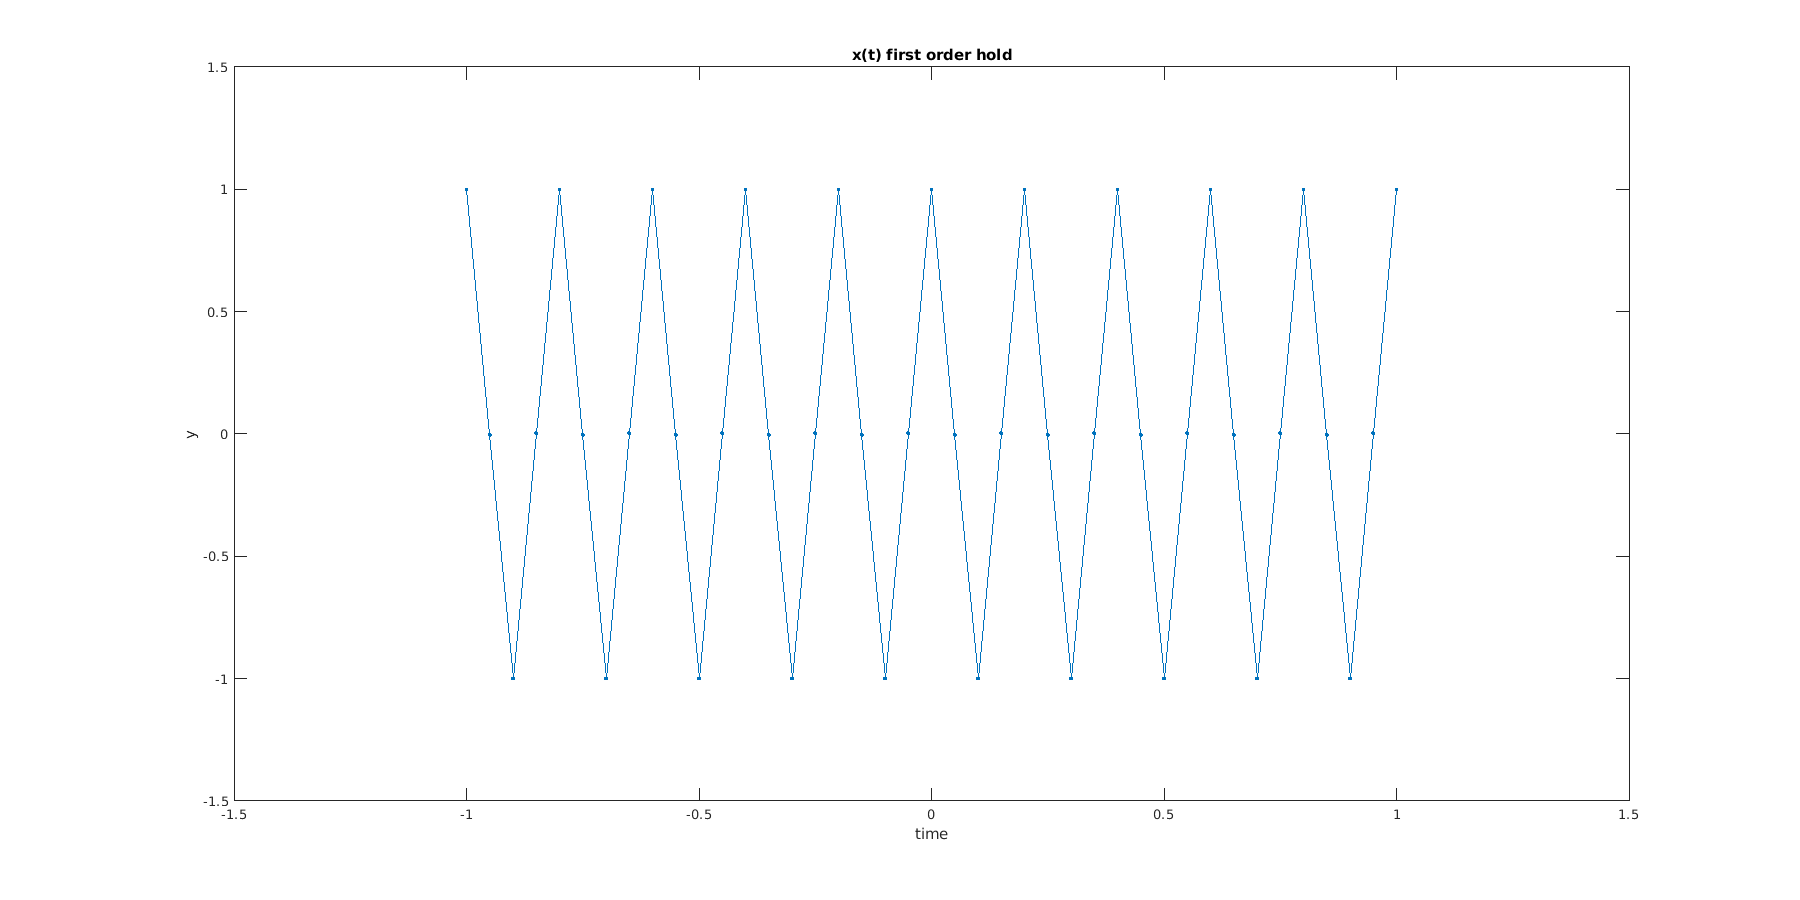

figure;
set(gcf,'position',[0,0,1800,900]);
plot(n1/fs,x(n1), '.-', 'markersize', 6)
title("x(t) first order hold");
xlabel("time");
ylabel("y")
ylim([-1.5,1.5]);
xlim([-1.5,1.5]);

## b

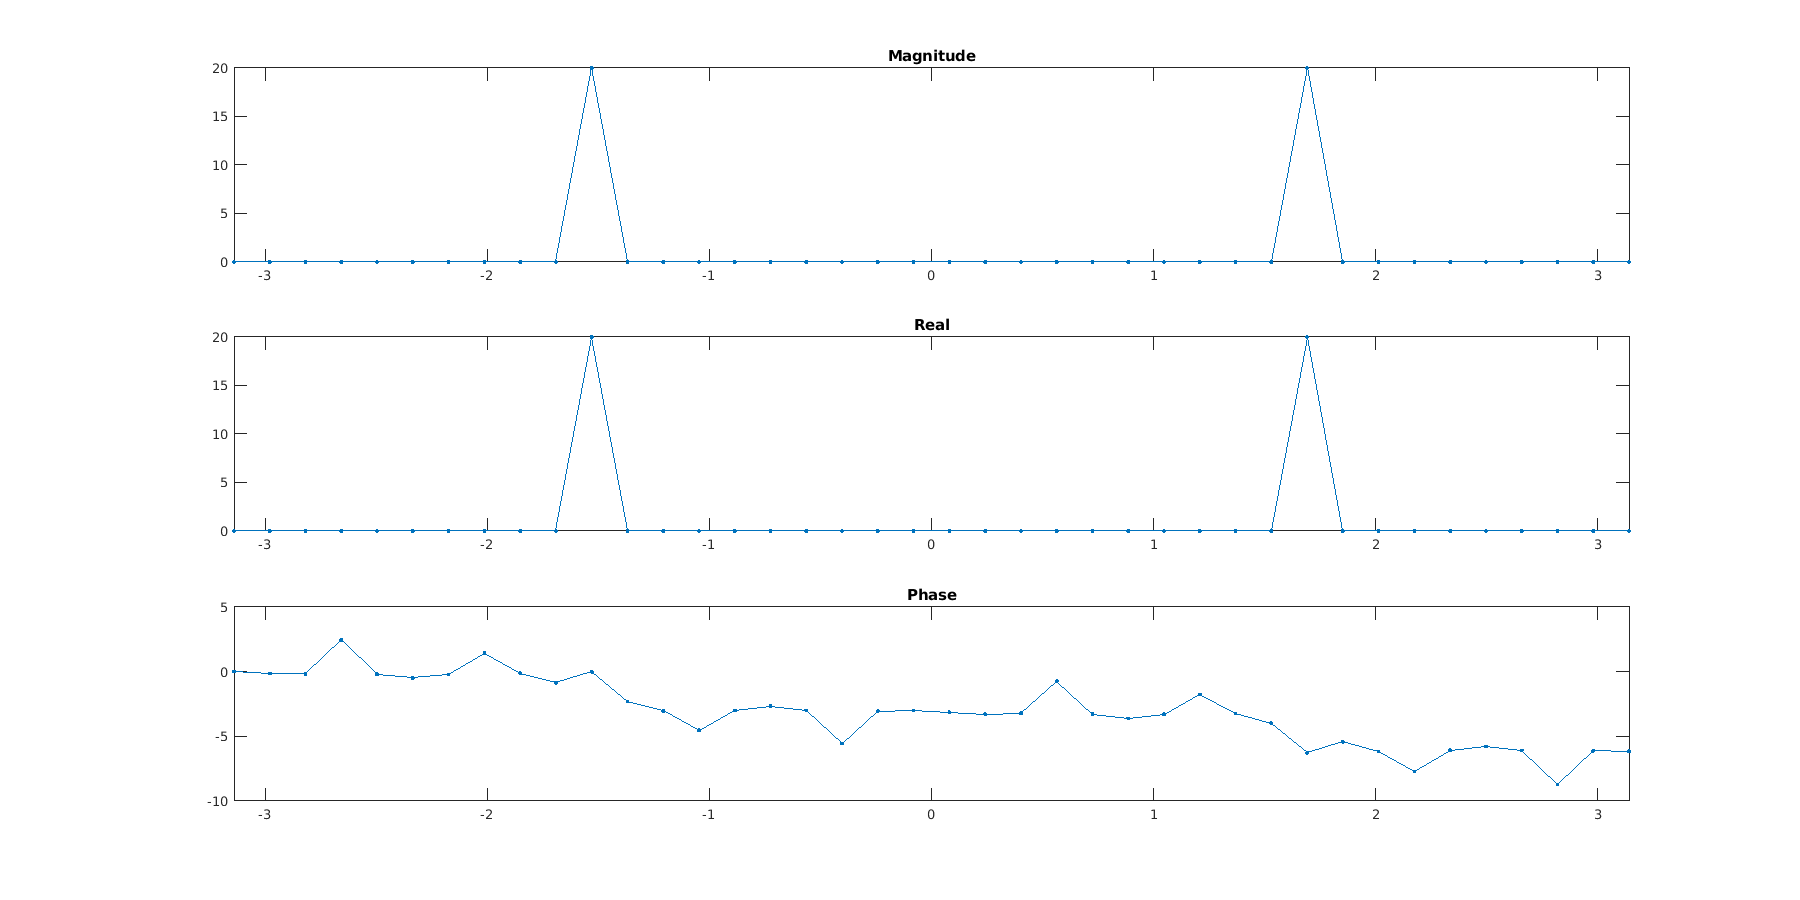

%fft_plot(fftshift(fft(x(n1))));
fft_plot(fftshift(fft(x(n))));

## c

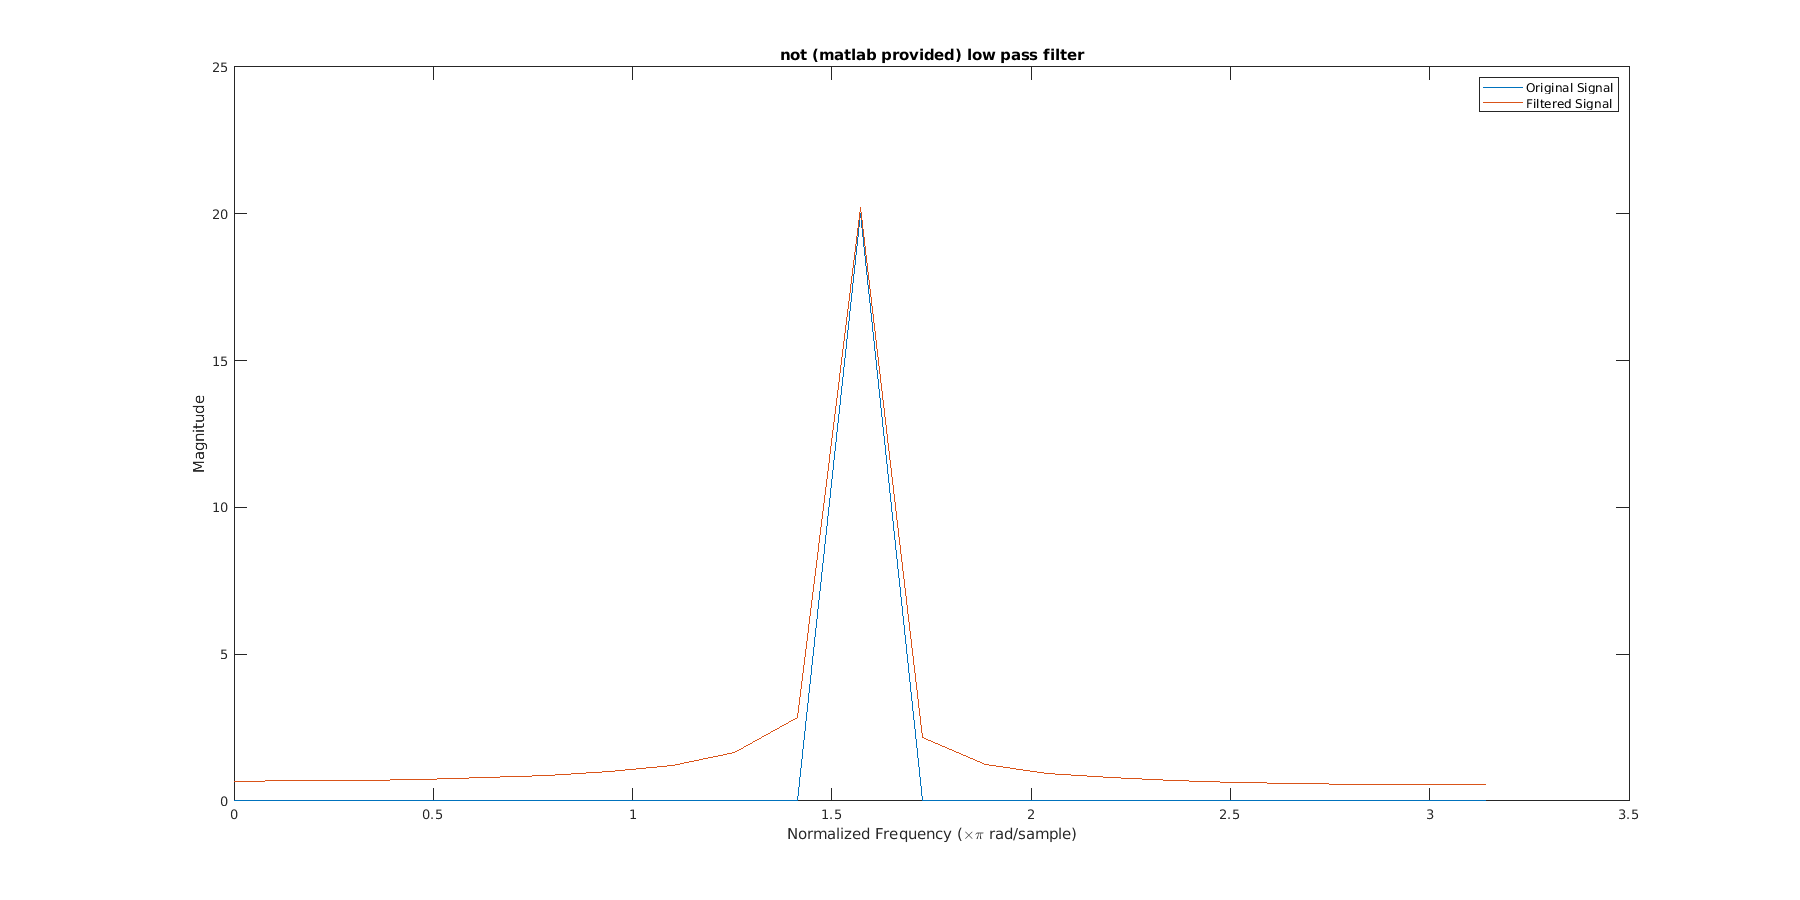

d = fdesign.lowpass('Fp,Fst,Ap,Ast',0.5,0.505,1,fs);
Hd = design(d,'equiripple');
%fvtool(Hd);
y = filter(Hd,x(n)) .* fs ;
freq = 0:(2*pi)/numel(n):pi;
xdft = fft(x(n));
ydft = fft(y);
figure;
set(gcf,'position',[0,0,1800,900]);
plot(freq,abs(xdft(1:length(x(n))/2+1)))
hold on
plot(freq,abs(ydft(1:length(y)/2+1)))
hold off
legend('Original Signal','Filtered Signal')
ylabel('Magnitude')
xlabel('Normalized Frequency (\times\pi rad/sample)')
title("not (matlab provided) low pass filter");

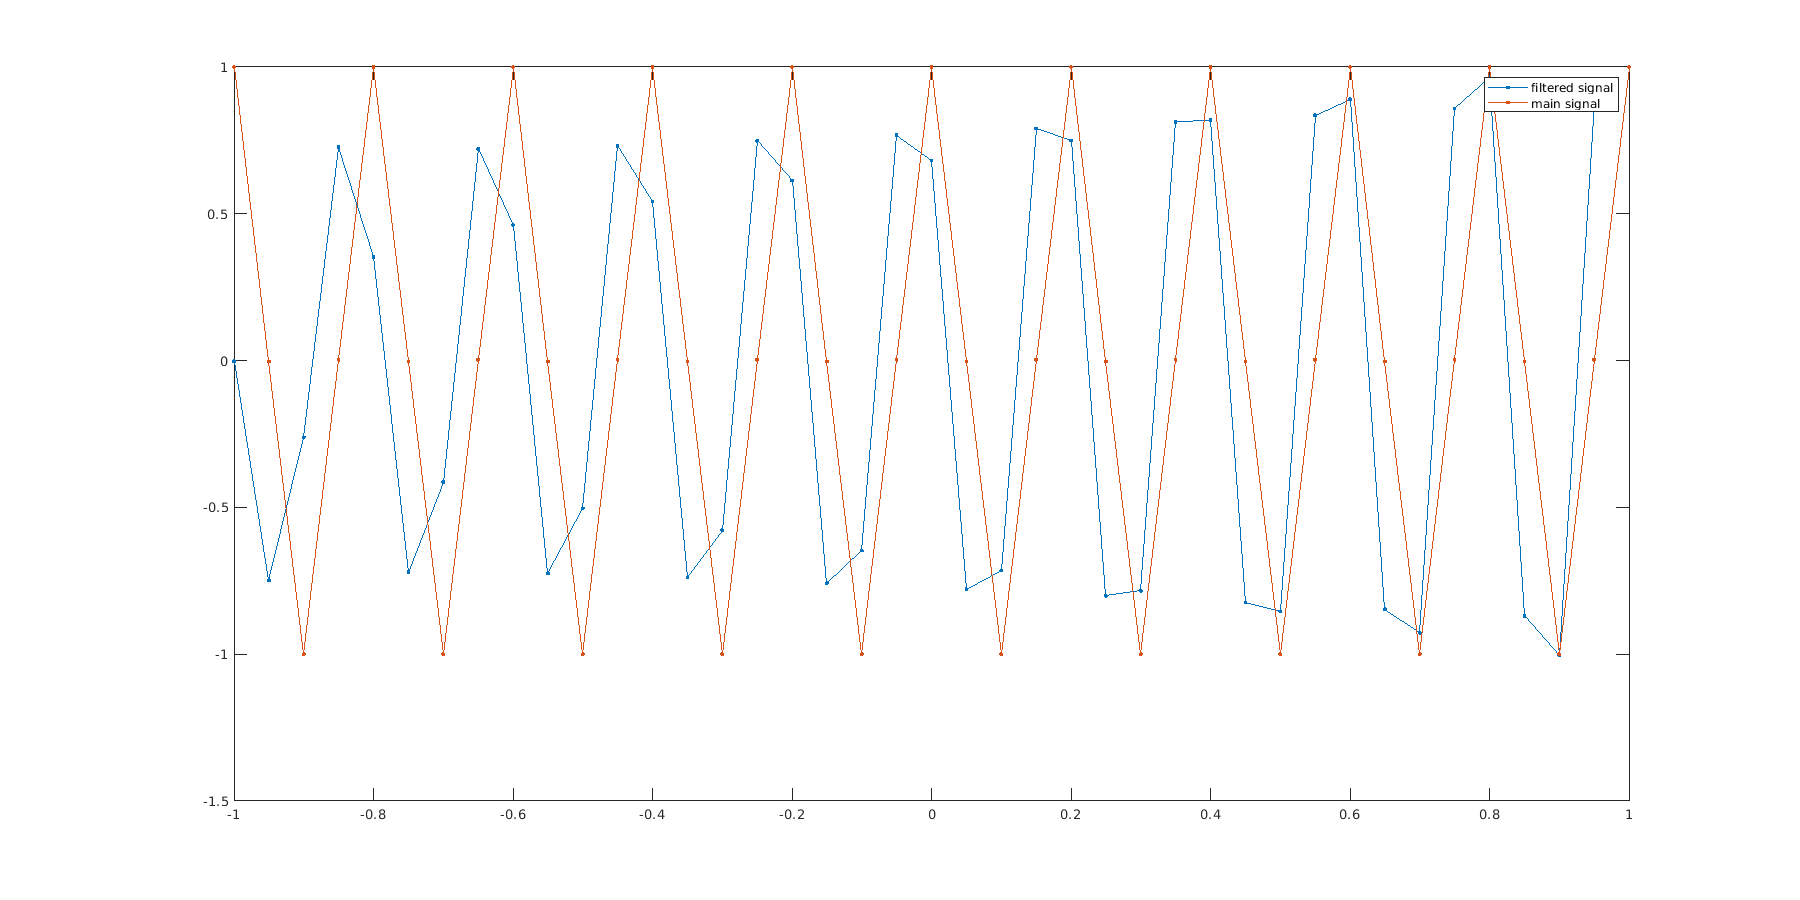

y = ifft(ifftshift(ydft));
figure;
set(gcf,'position',[0,0,1800,900]);
plot(n/fs,y,'.-', 'markersize', 6);
hold on
plot(n1/fs,x(n1), '.-', 'markersize', 6);
legend("filtered signal","main signal");
hold off;

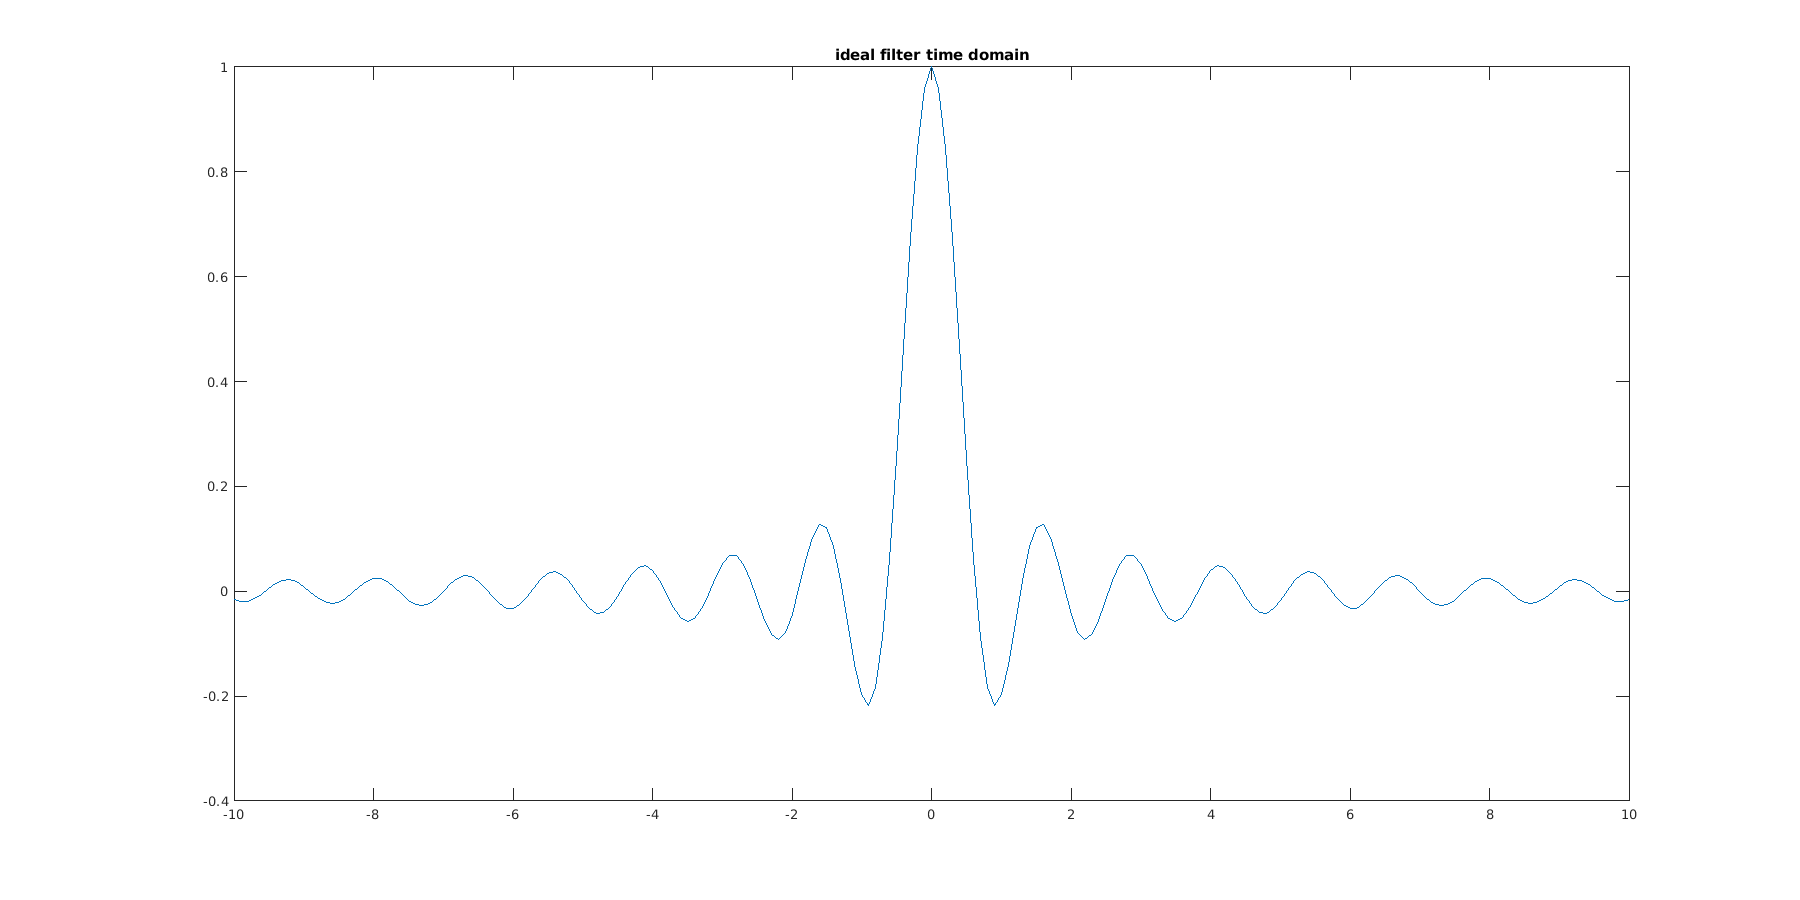

shg;
ideal_filter = sinc(1/fs * 10 *pi.*n);
ideal_filter_f = @(t) sinc(1/fs * 10 *pi.*t);
t1 = -10:0.1:10;
set(gcf,'position',[0,0,1800,900]);
plot(t1,ideal_filter_f(t1));
title("ideal filter time domain")

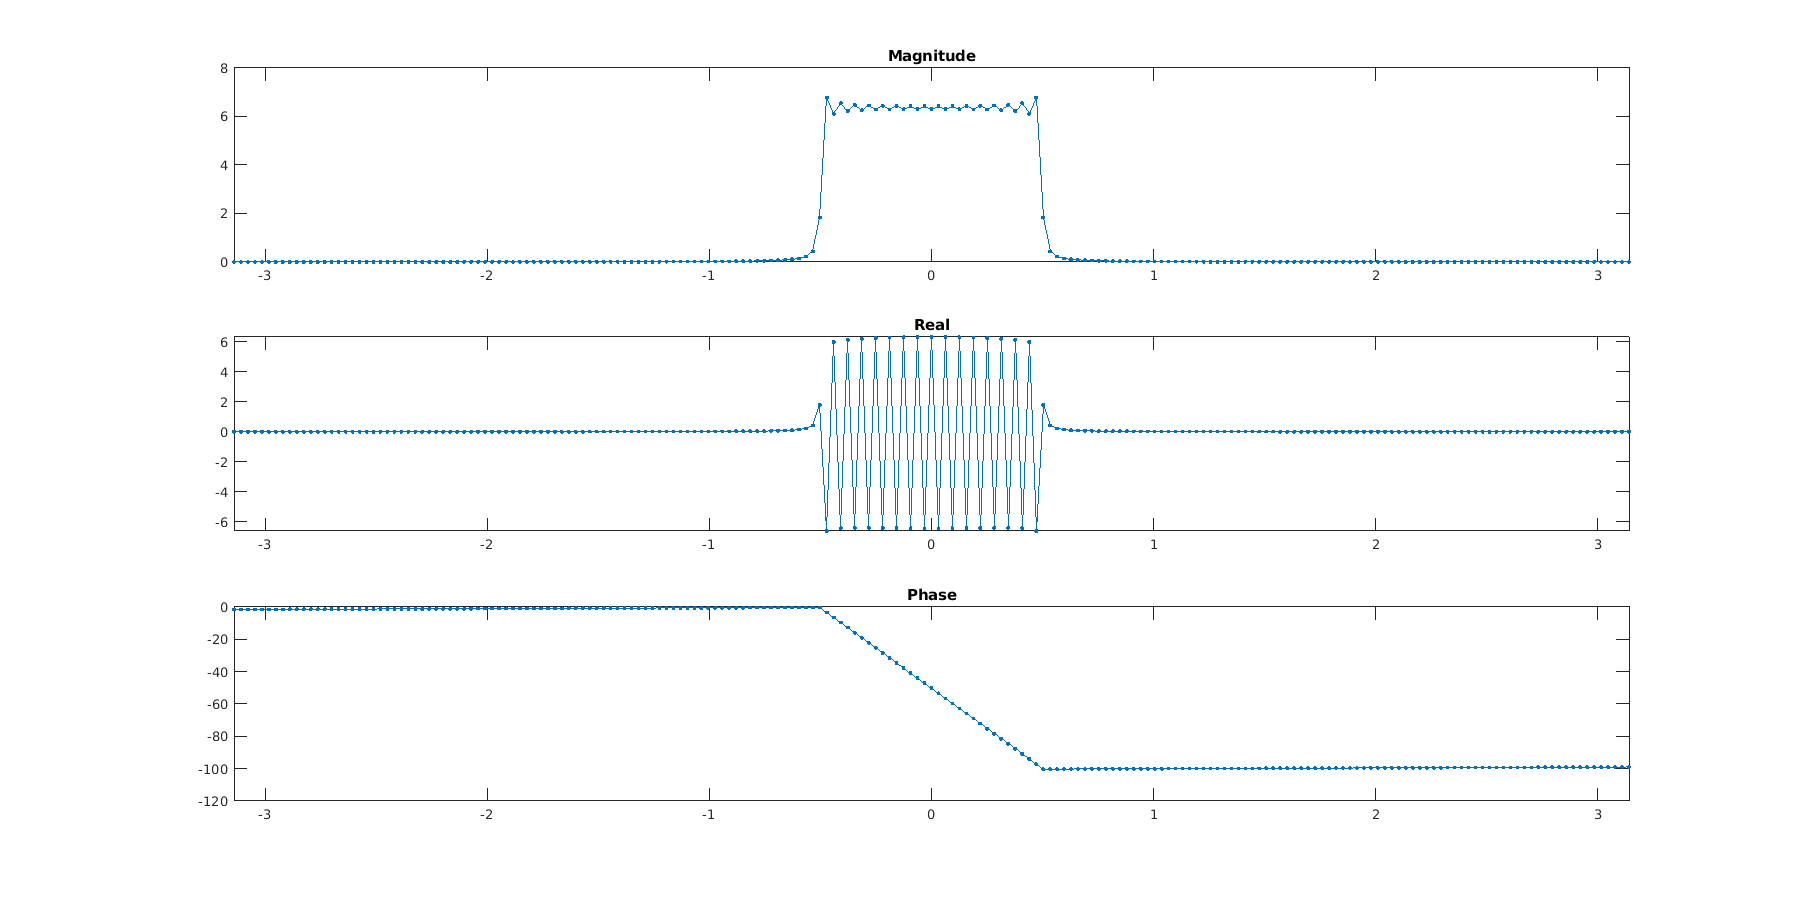

fft_plot(fftshift(fft(ideal_filter_f(t1))));

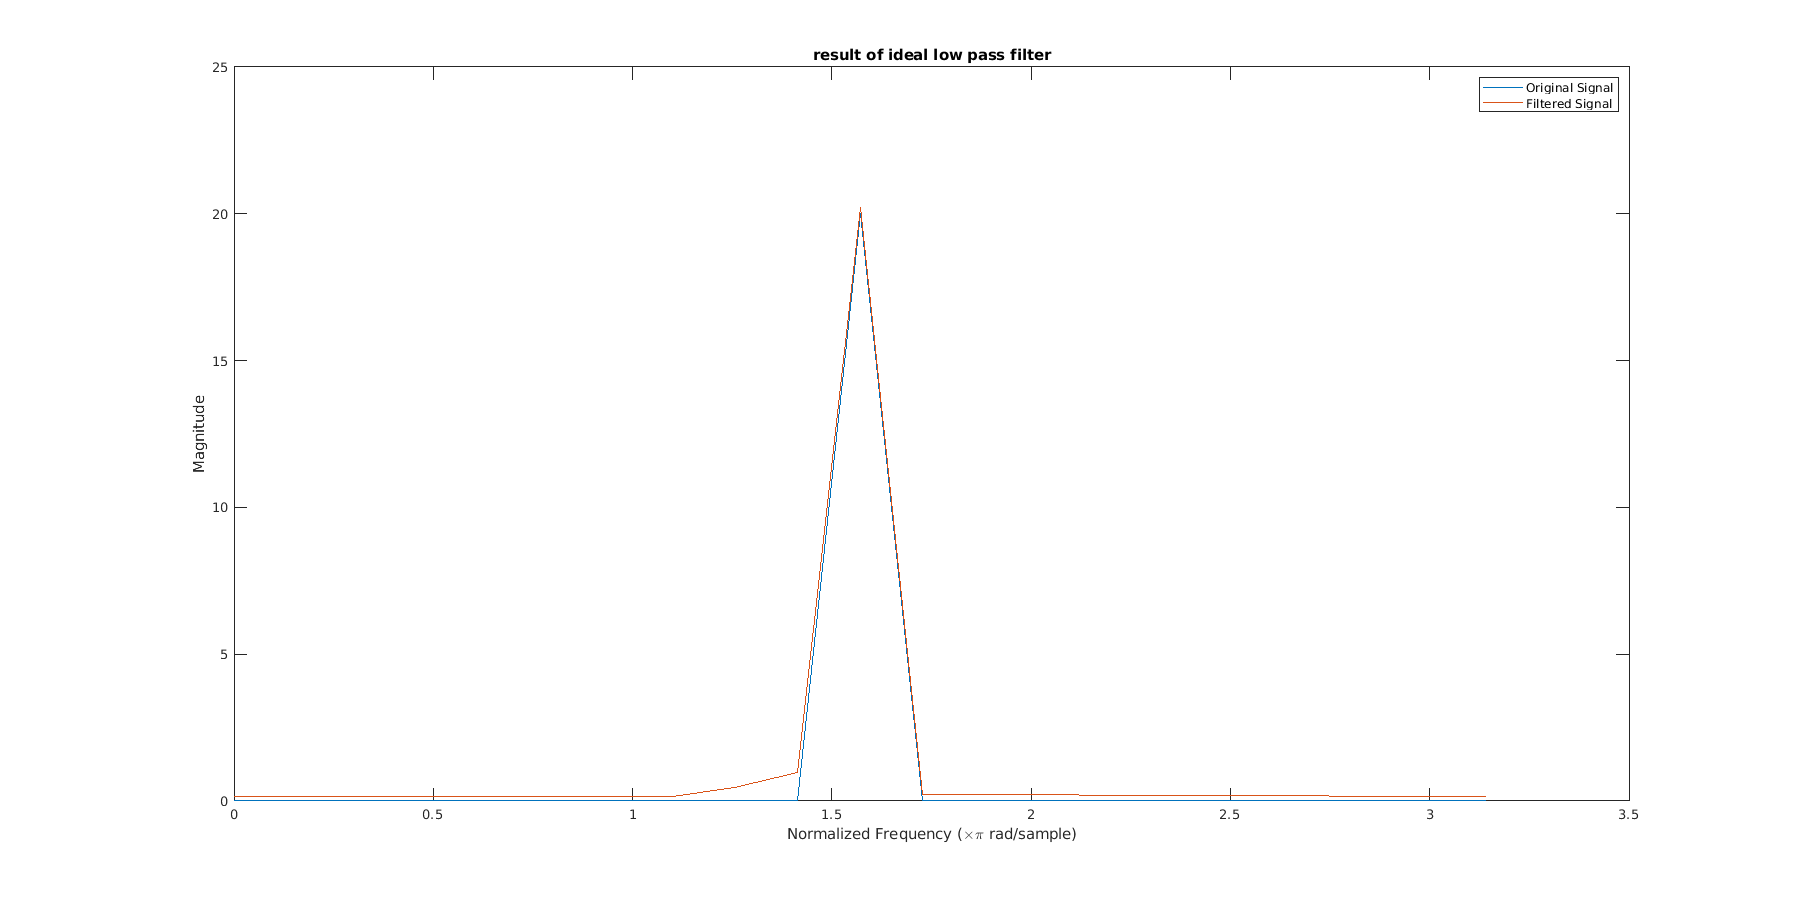

convolved = conv(ideal_filter,x(n),"same") .* 20/25;
ydft = fft(convolved);
xdft = fft(x(n));
freq = 0:(2*pi)/numel(n):pi;
figure;
set(gcf,'position',[0,0,1800,900]);
plot(freq,abs(xdft(1:length(x(n))/2+1)))
hold on
plot(freq,abs(ydft(1:length(y)/2+1)))
hold off
legend('Original Signal','Filtered Signal')
ylabel('Magnitude')
xlabel('Normalized Frequency (\times\pi rad/sample)')
title("result of ideal low pass filter")

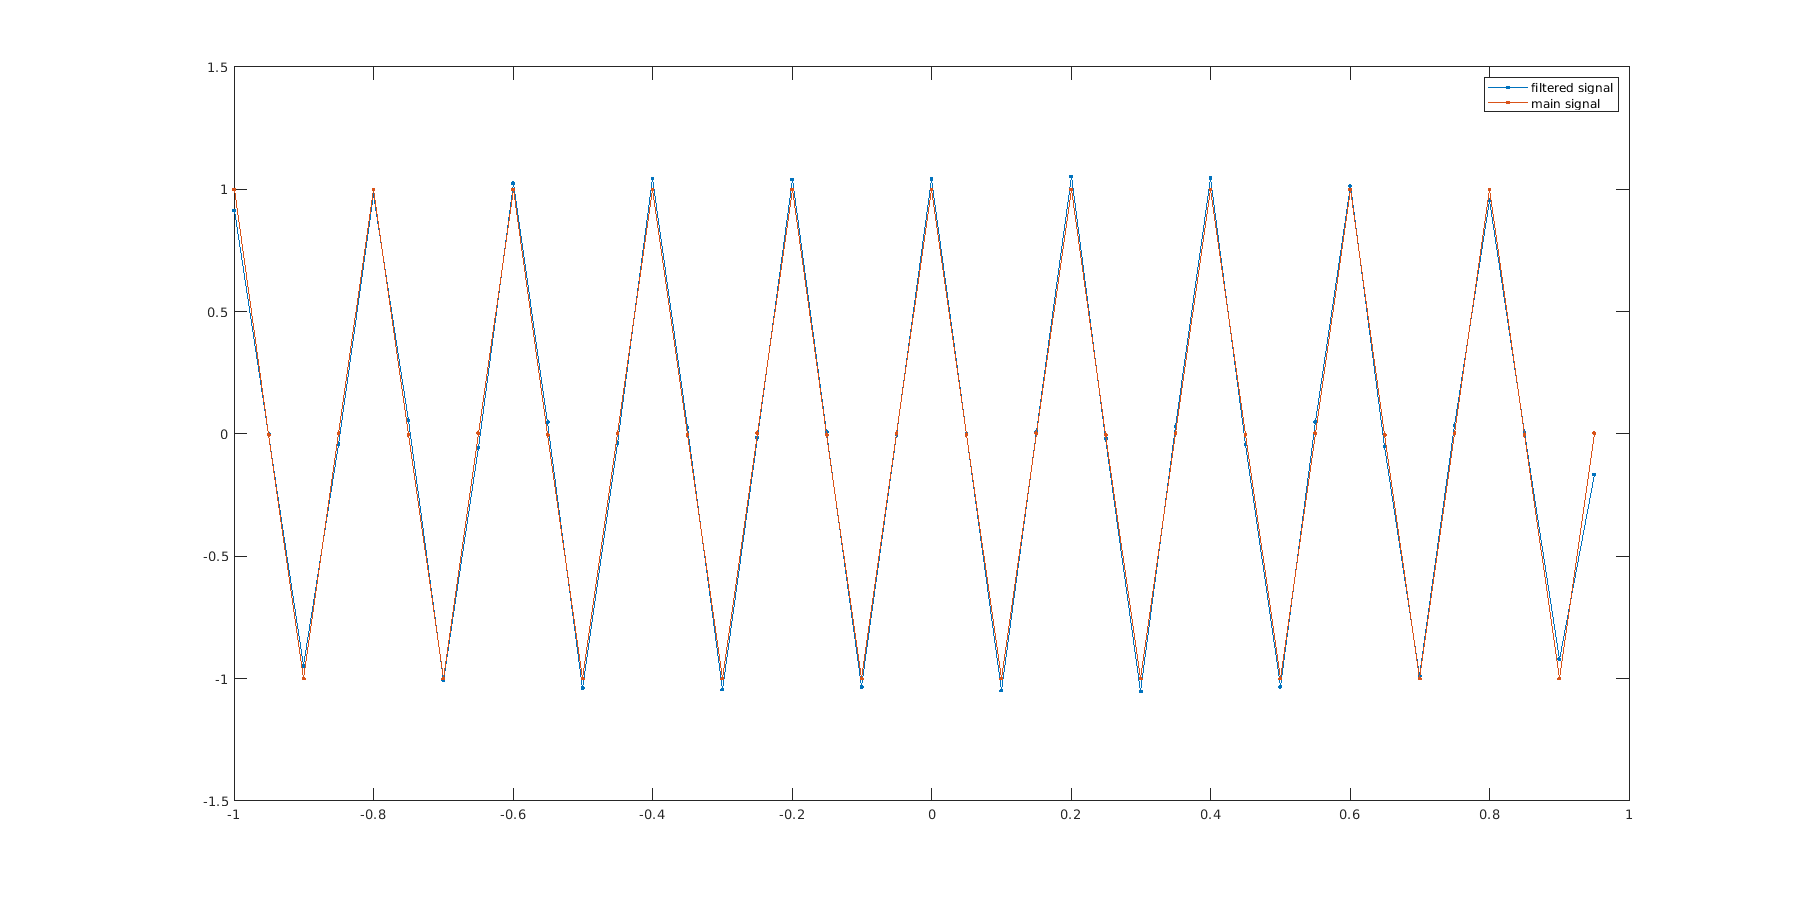


y = ifft(ifftshift(ydft));
figure;
set(gcf,'position',[0,0,1800,900]);
plot(n/fs,y,'.-', 'markersize', 6);
hold on
plot(n/fs,x(n), '.-', 'markersize', 6);
legend("filtered signal","main signal");
hold off;

## d

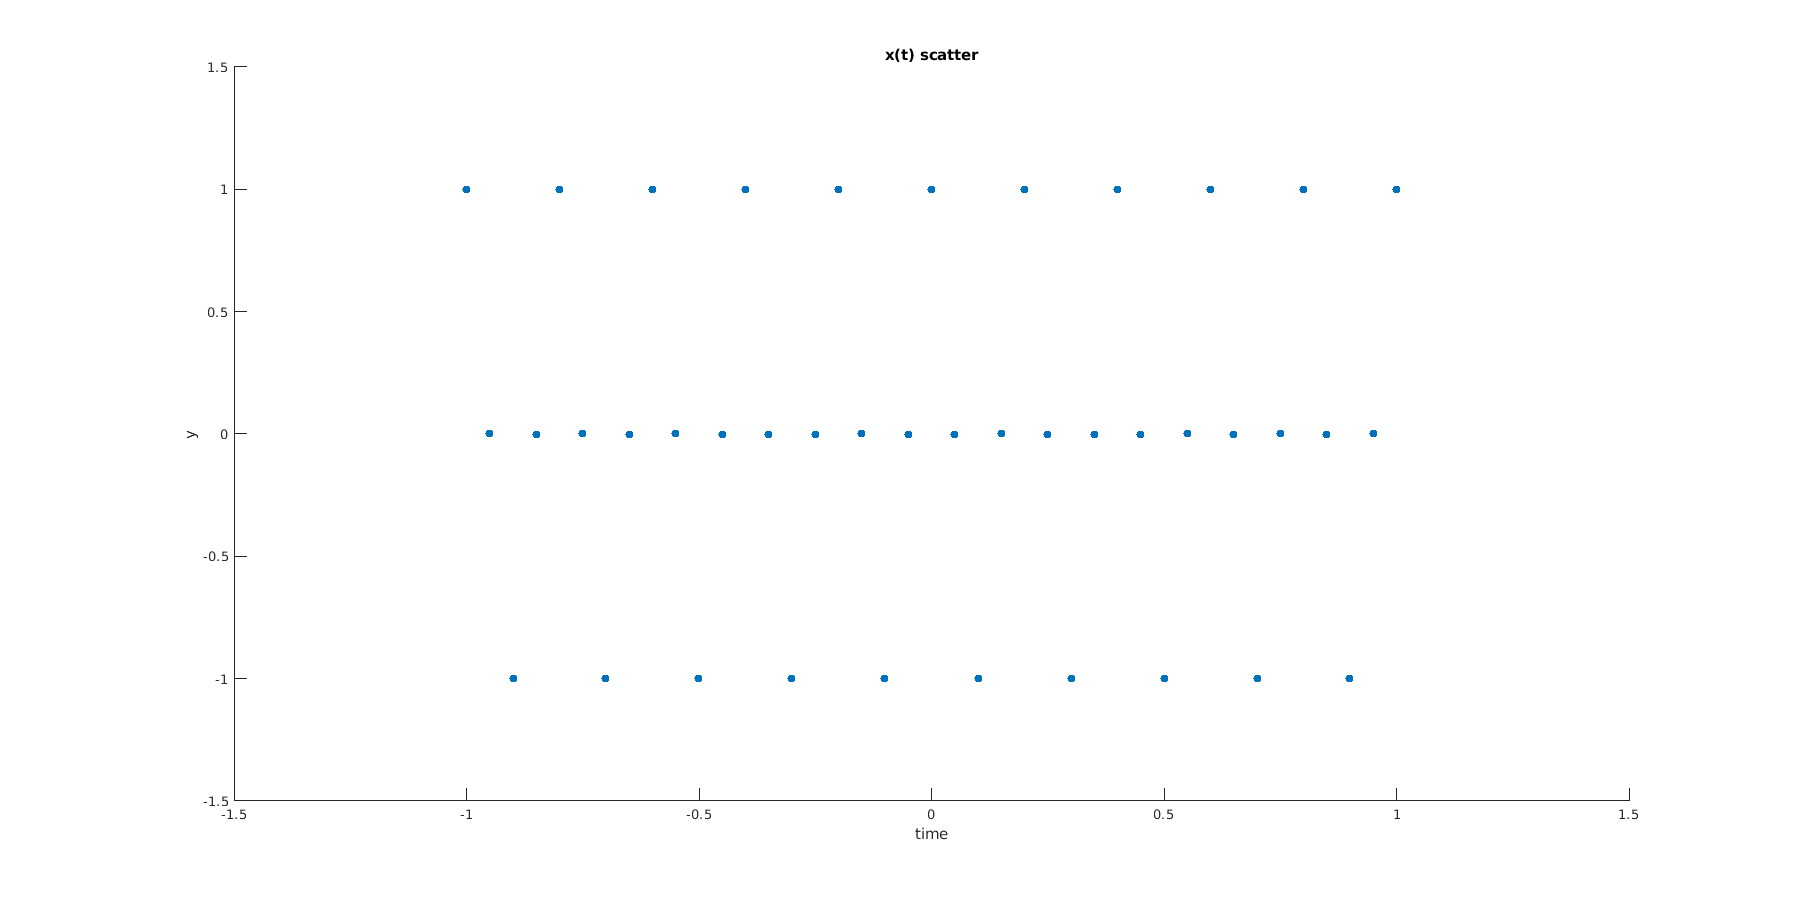

x = @(n) cos(1/fs * 30 *pi.*n);
n = -fs:fs-1;
n1 = -fs:fs;
figure;
set(gcf,'position',[0,0,1800,900]);
scatter(n1/fs,x(n1),"filled")
title("x(t) scatter");
xlabel("time");
ylabel("y")
ylim([-1.5,1.5]);
xlim([-1.5,1.5]);

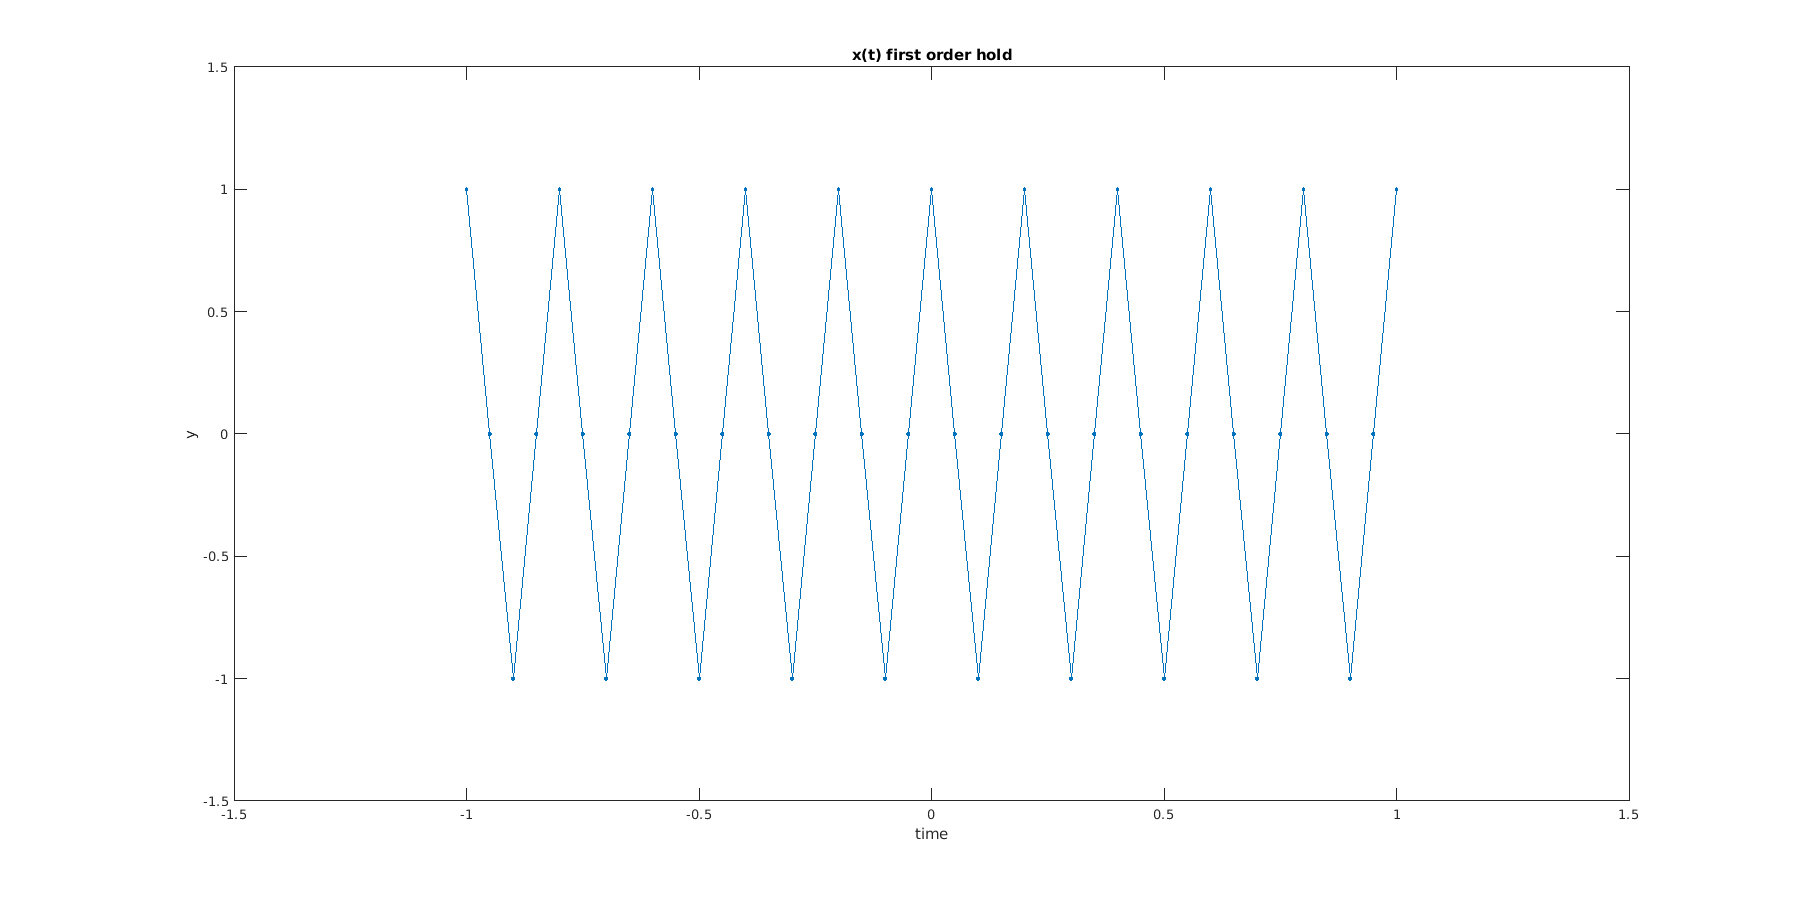

figure;
set(gcf,'position',[0,0,1800,900]);
plot(n1/fs,x(n1), '.-', 'markersize', 6)
title("x(t) first order hold");
xlabel("time");
ylabel("y")
ylim([-1.5,1.5]);
xlim([-1.5,1.5]);

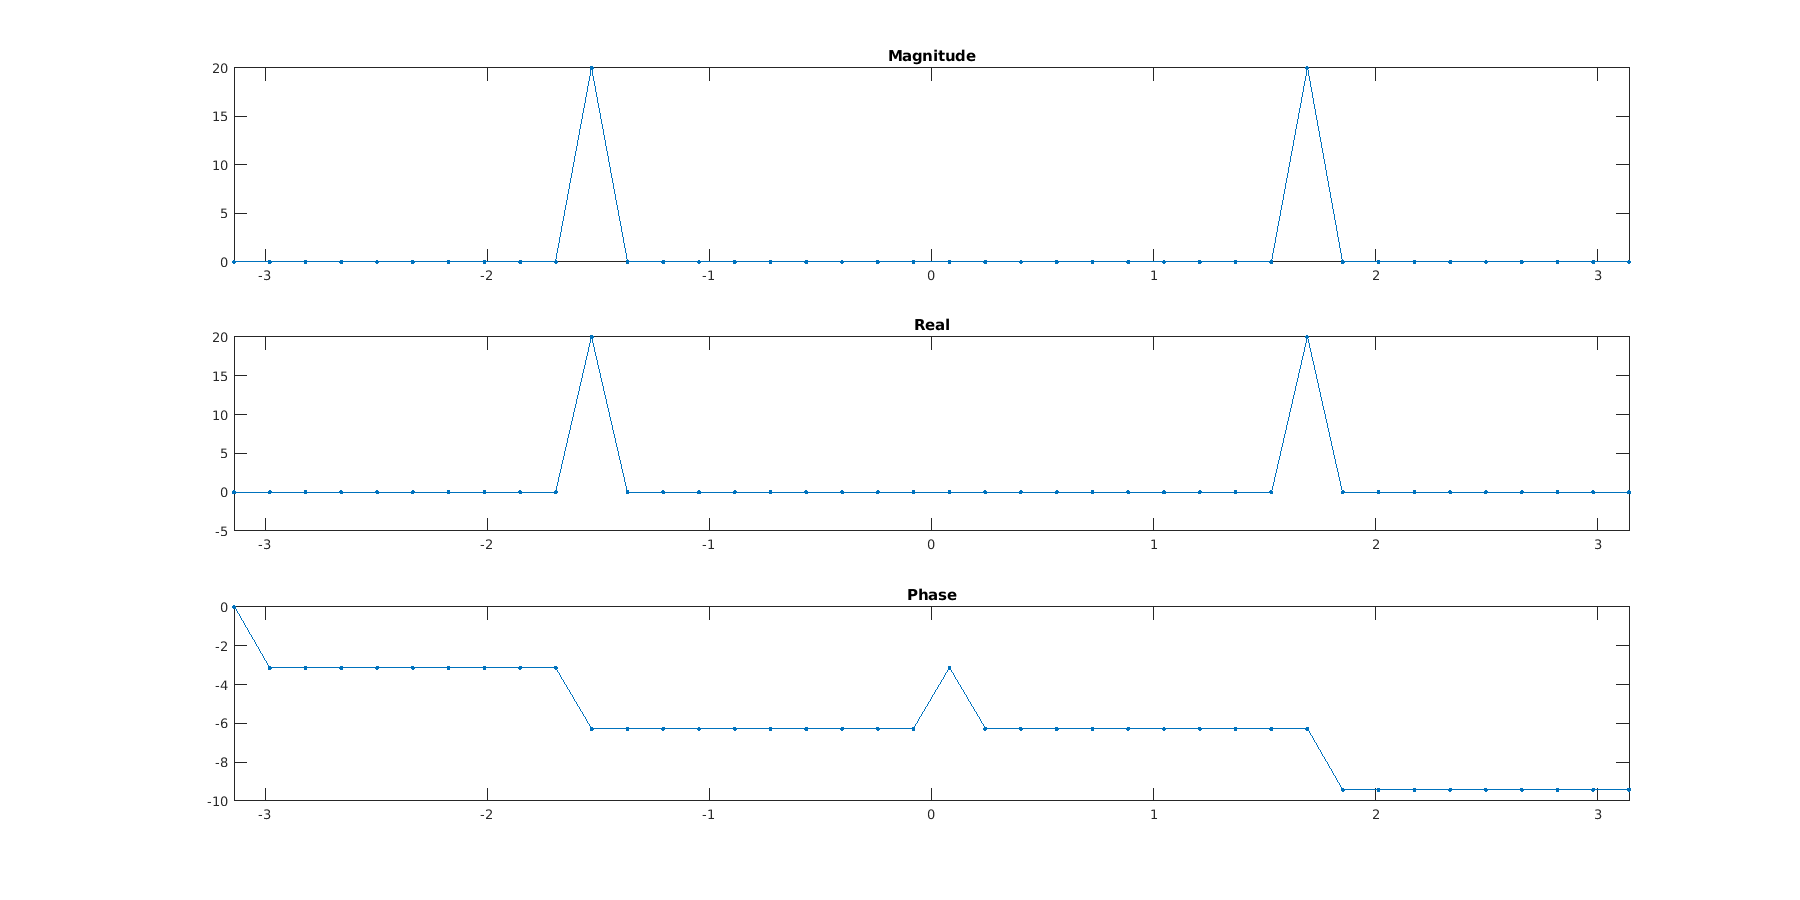

shg;
%fft_plot(fftshift(fft(x(n1))));
fft_plot(fftshift(fft(x(n))));

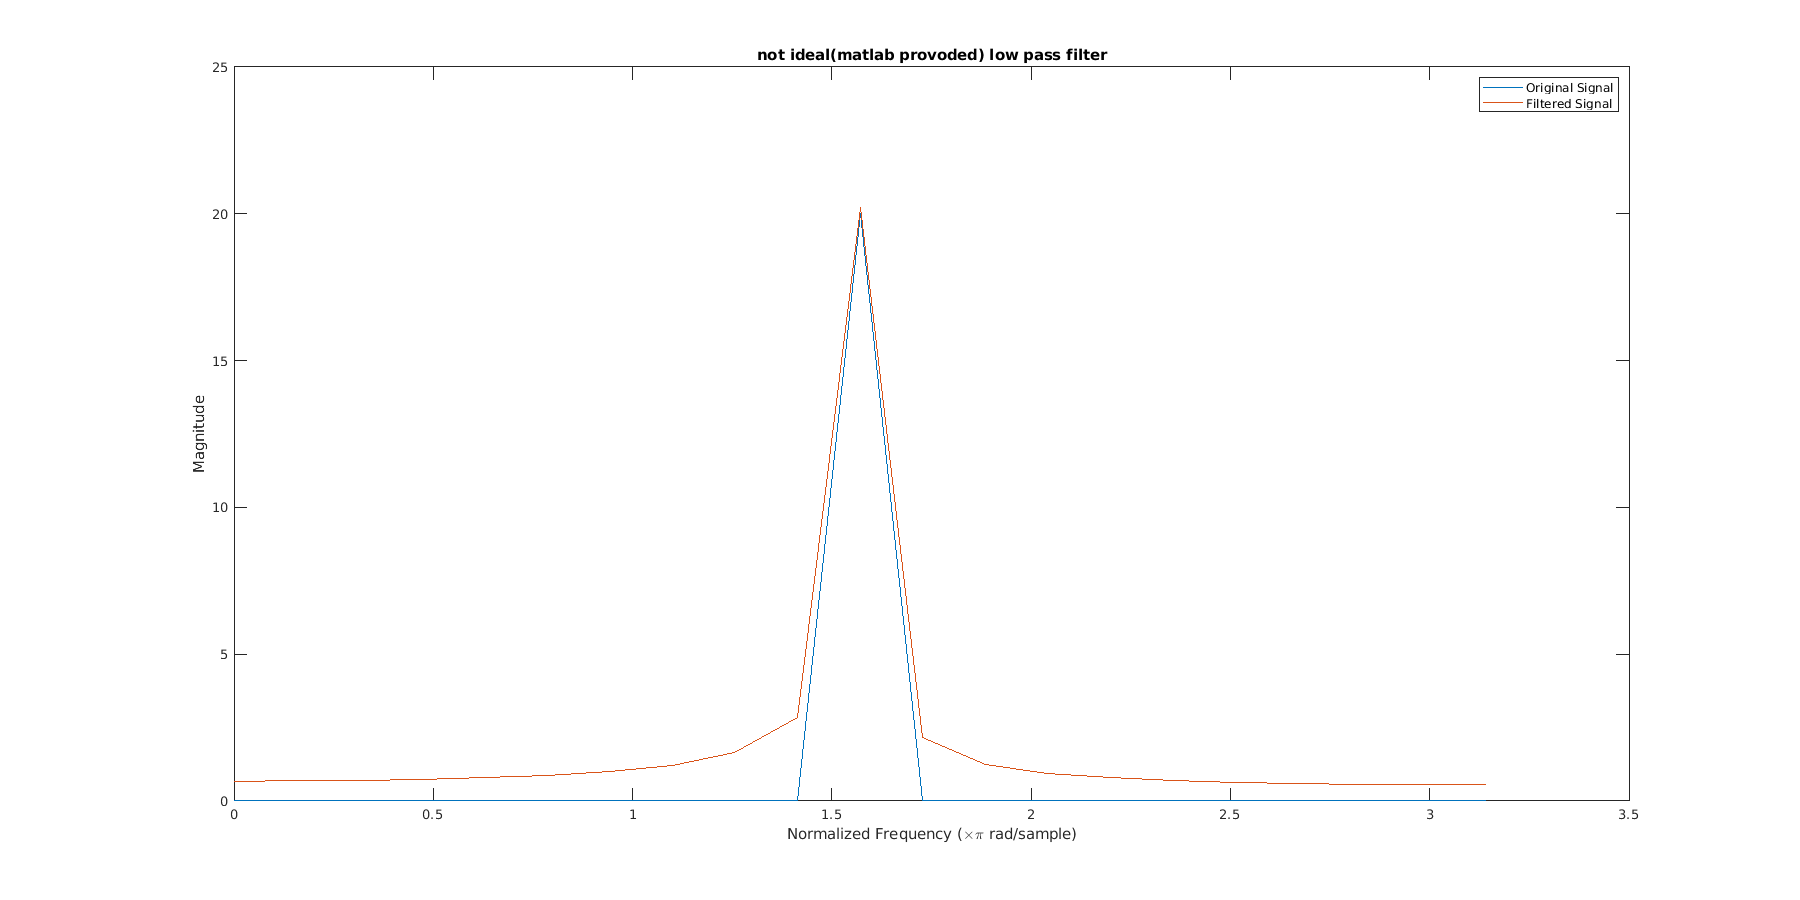


y = filter(Hd,x(n)) .* fs ;
freq = 0:(2*pi)/numel(n):pi;
xdft = fft(x(n));
ydft = fft(y);
figure;
set(gcf,'position',[0,0,1800,900]);
plot(freq,abs(xdft(1:length(x(n))/2+1)))
hold on
plot(freq,abs(ydft(1:length(y)/2+1)))
hold off
legend('Original Signal','Filtered Signal')
ylabel('Magnitude')
xlabel('Normalized Frequency (\times\pi rad/sample)')
title("not ideal(matlab provoded) low pass filter");

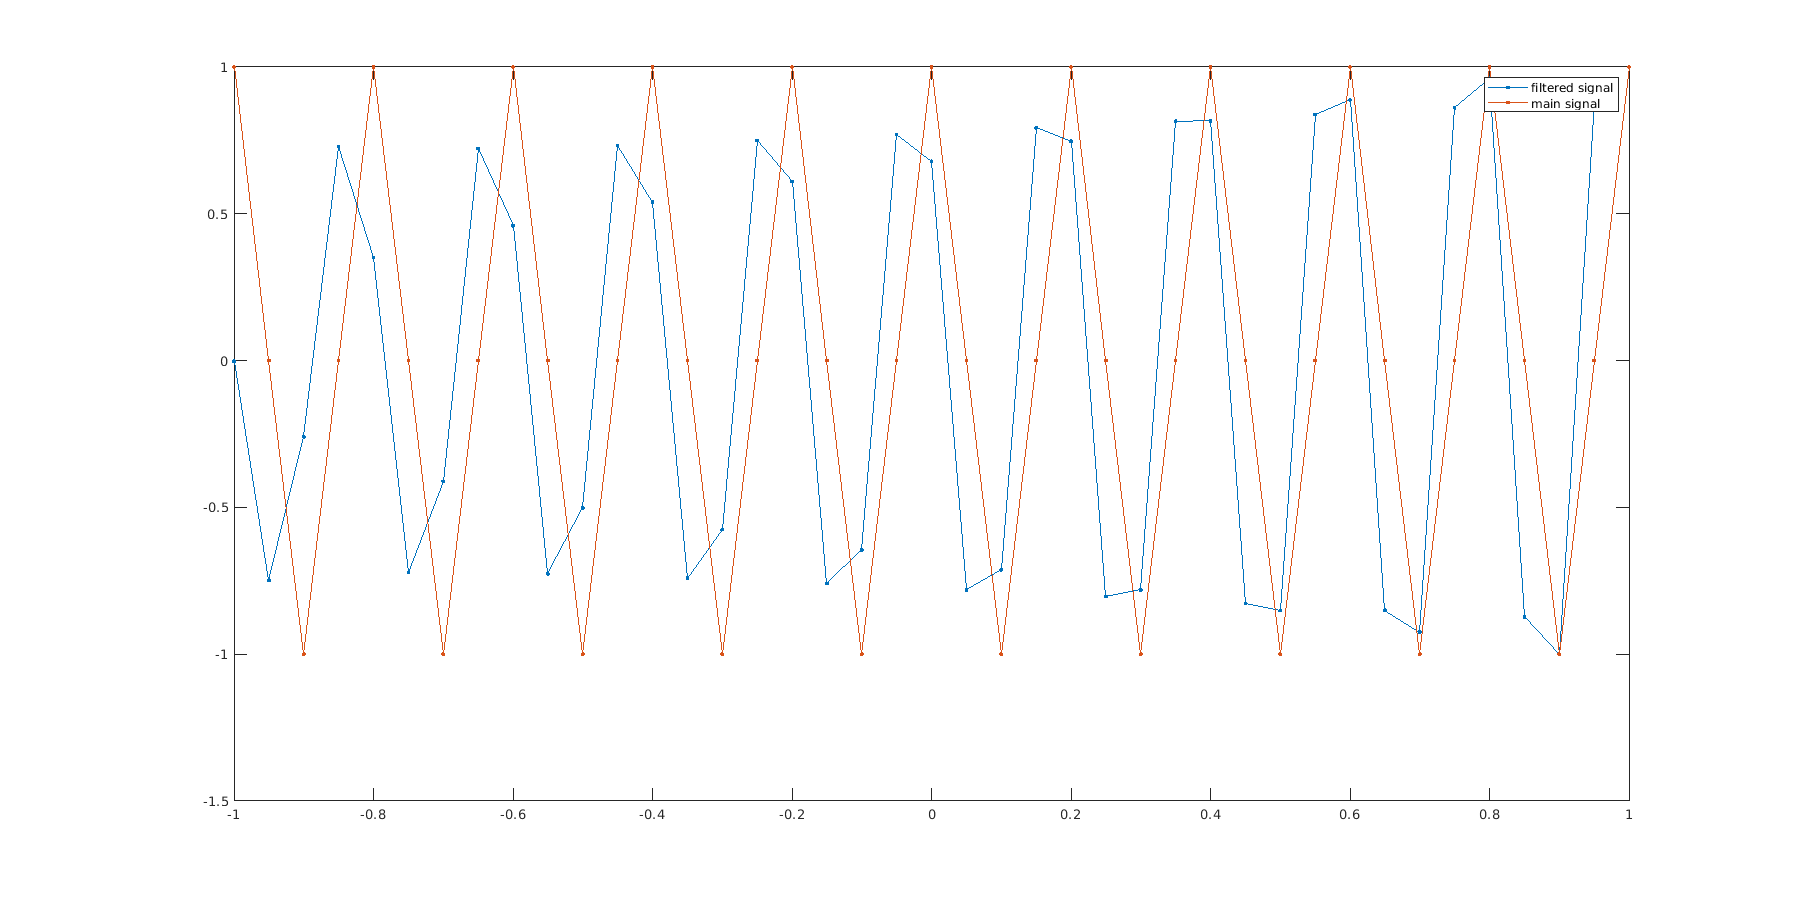

y = ifft(ifftshift(ydft));
figure;
set(gcf,'position',[0,0,1800,900]);
plot(n/fs,y,'.-', 'markersize', 6);
hold on
plot(n1/fs,x(n1), '.-', 'markersize', 6);
legend("filtered signal","main signal");
hold off;

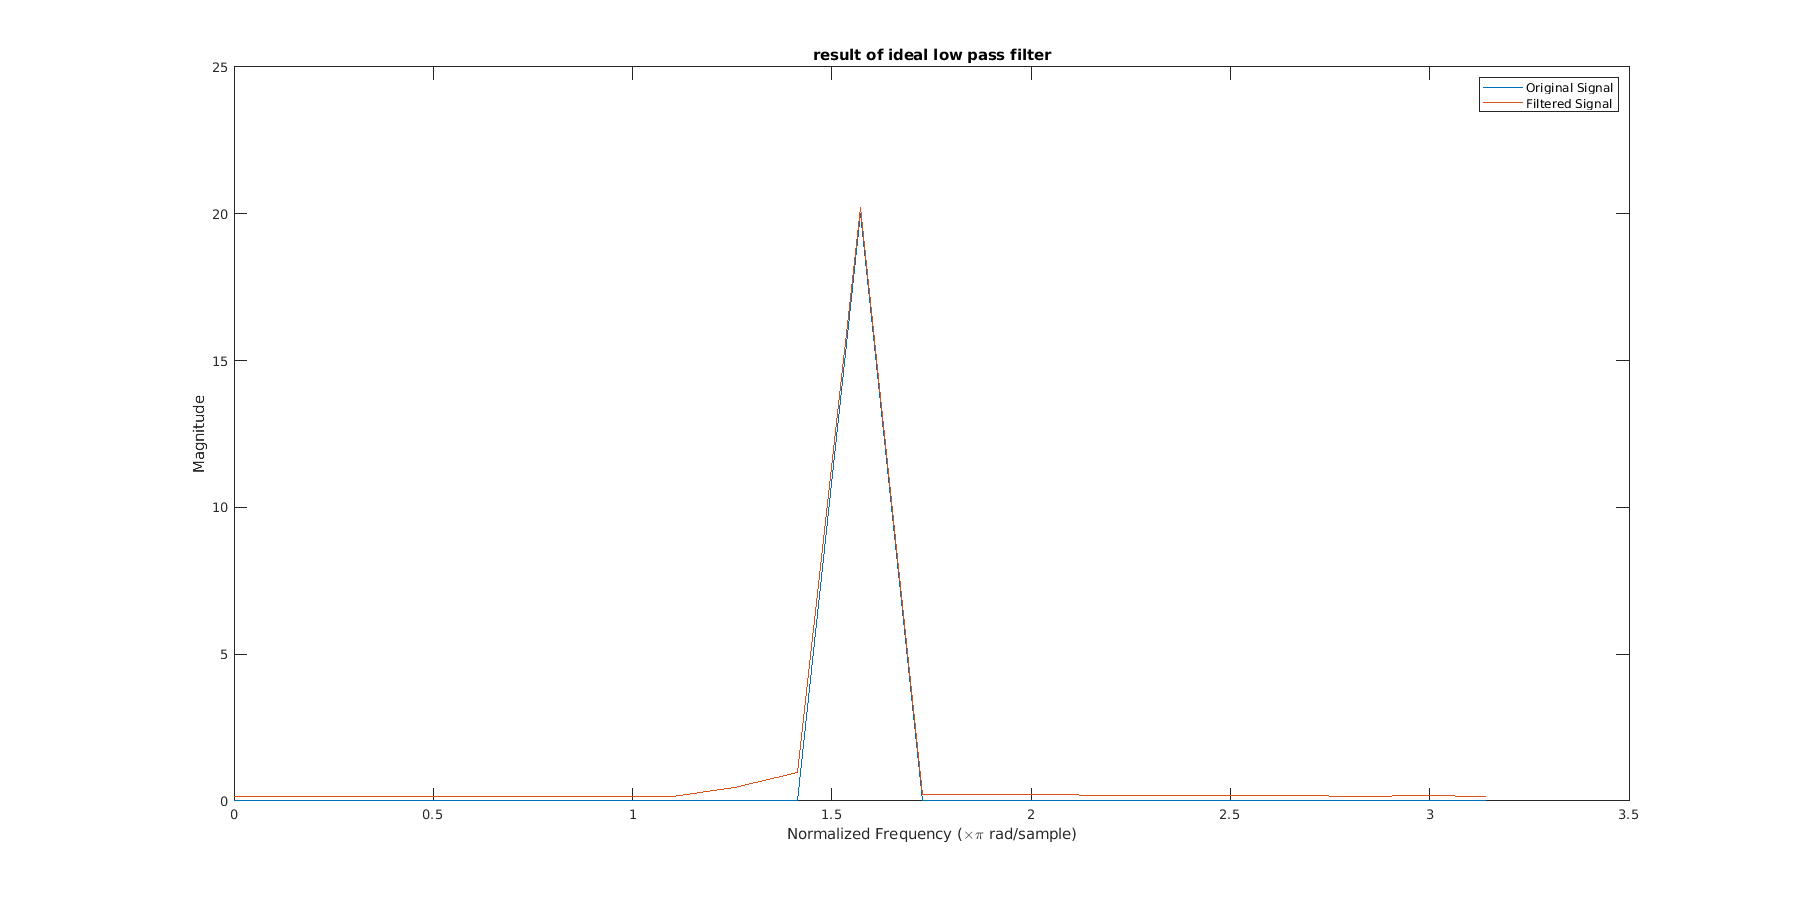

ideal_filter = sinc(1/fs * 10 *pi.*n) * 20/25;
convolved = conv(ideal_filter,x(n),"same");
ydft = fft(convolved);
xdft = fft(x(n));
Domega = (2*pi)/numel(n);
freq = 0:(2*pi)/numel(n):pi;
plot(freq,abs(xdft(1:length(x(n))/2+1)))
hold on
plot(freq,abs(ydft(1:length(y)/2+1)))
hold off
legend('Original Signal','Filtered Signal')
ylabel('Magnitude')
xlabel('Normalized Frequency (\times\pi rad/sample)')
title("result of ideal low pass filter")

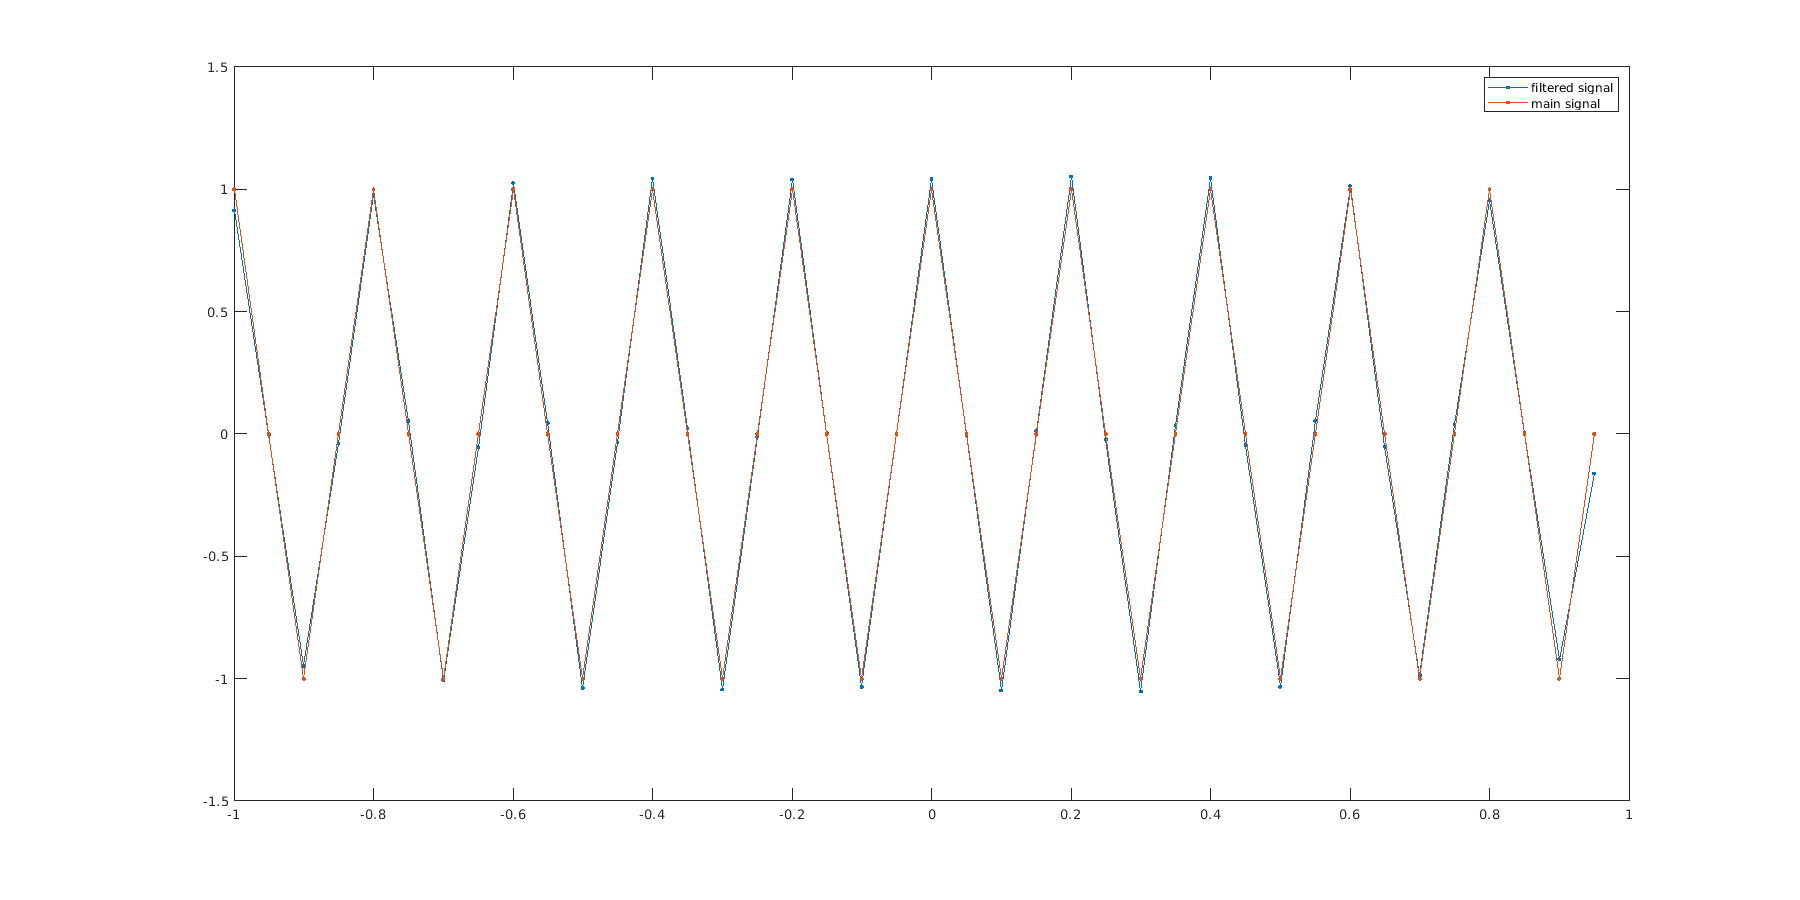

y = ifft(ifftshift(ydft));
figure;
set(gcf,'position',[0,0,1800,900]);
plot(n/fs,y,'.-', 'markersize', 6);
hold on
plot(n/fs,x(n), '.-', 'markersize', 6);
legend("filtered signal","main signal");
hold off;

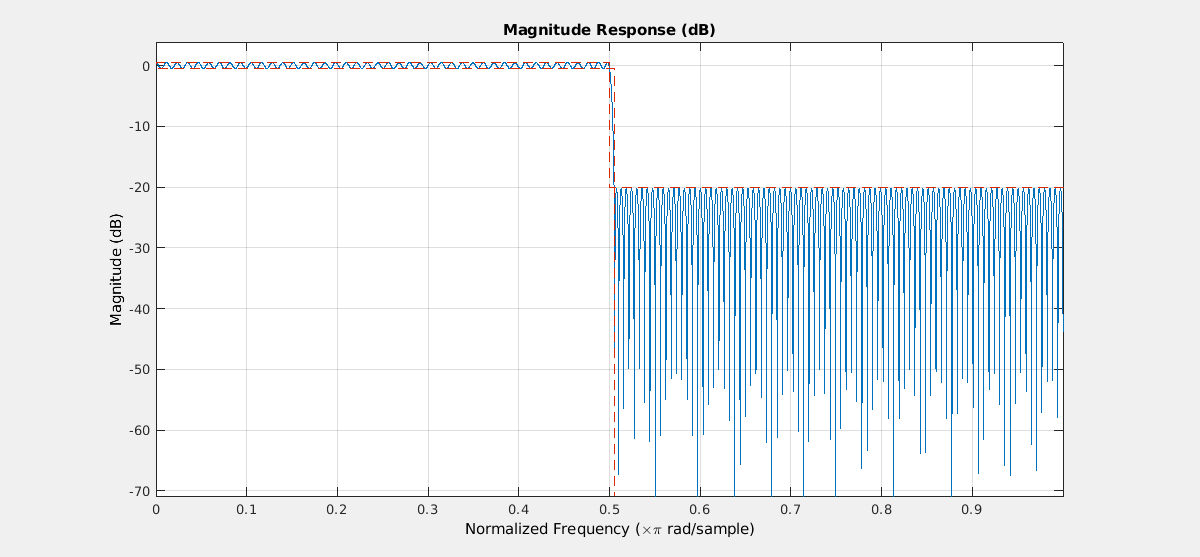

fvtool(Hd,'Analysis','magnitude')

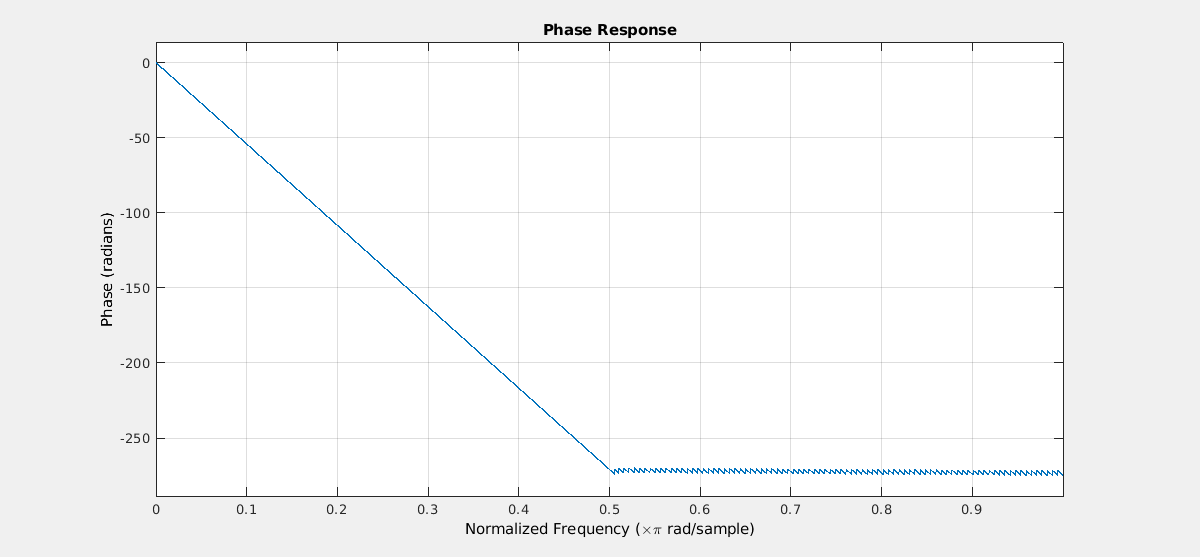

fvtool(Hd,'Analysis','phase')

# Part Two

t0 = 0.1;
fc = 250;
alpha = 0.8;
m = @(t) sinc(100 .* t) .* (0<=t & t <= t0);
c = @(t) cos(2*pi*fc .* t);
u = @(t) (1+ alpha * m(t)) .* c(t);
u2 = @(t) m(t) .* c(t);
t = -0.05:0.0001:t0+0.05;
t2= 0:0.001:10*t0;
%fft_plot(fftshift(fft(c(t2))));

## a

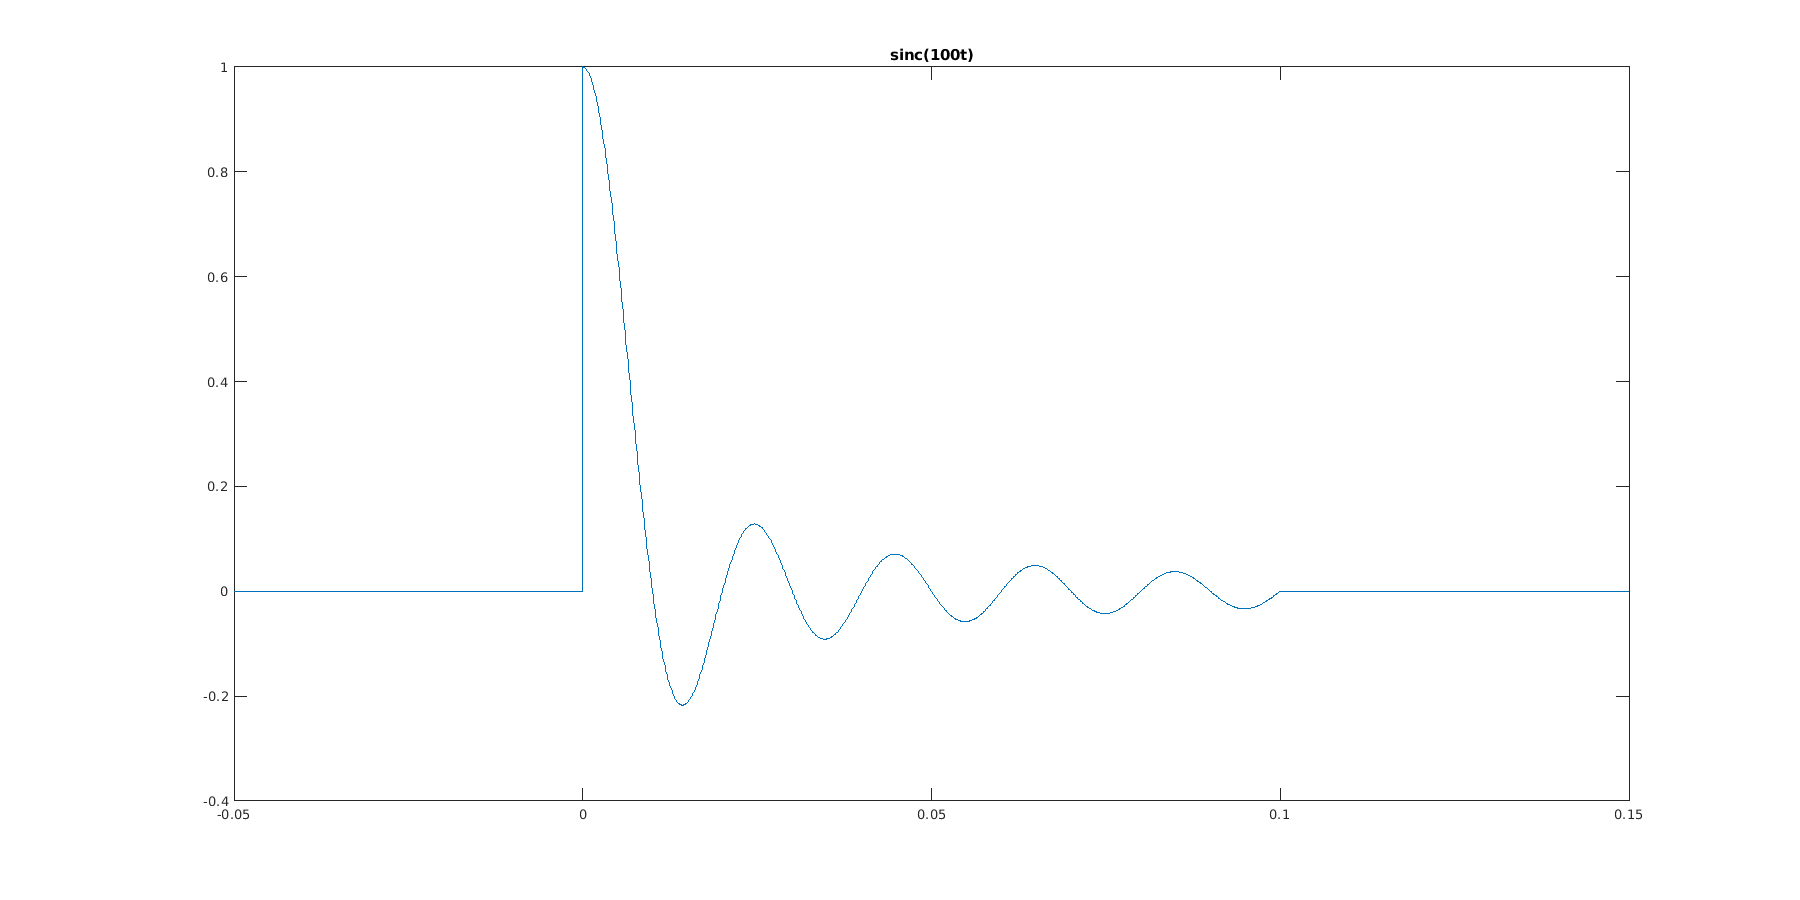

figure;
set(gcf,'position',[0,0,1800,900]);
plot(t,m(t));
title("sinc(100t)")

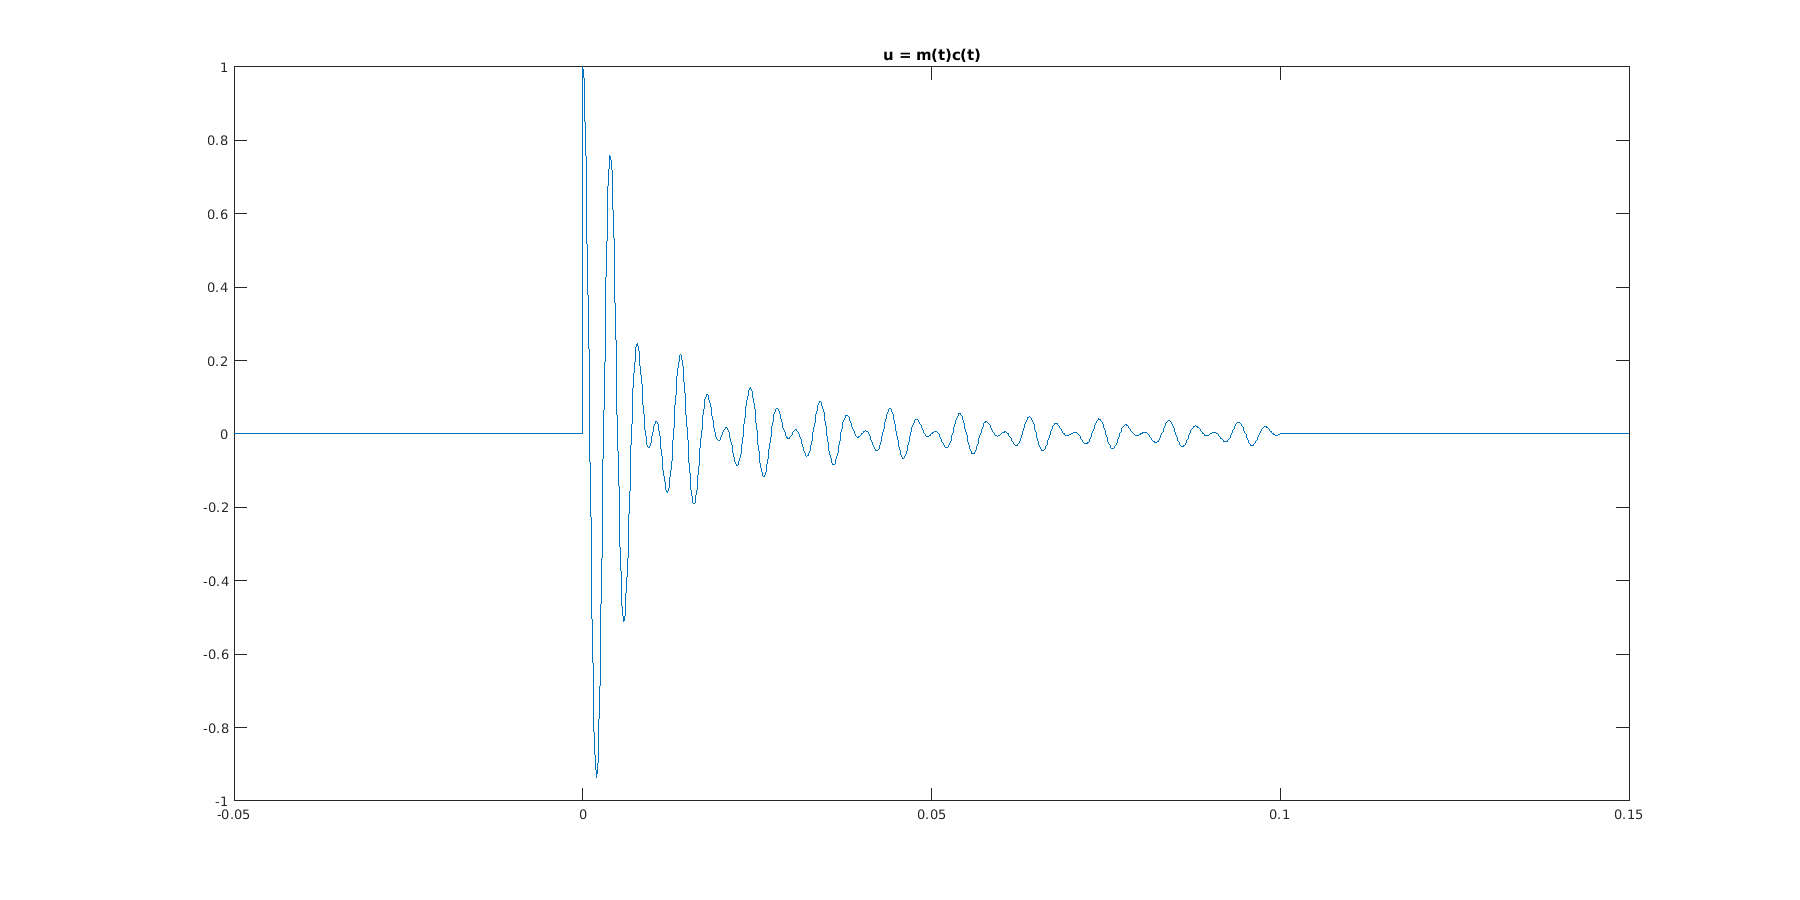

figure;
set(gcf,'position',[0,0,1800,900]);
plot(t,u2(t));
title("u = m(t)c(t)")

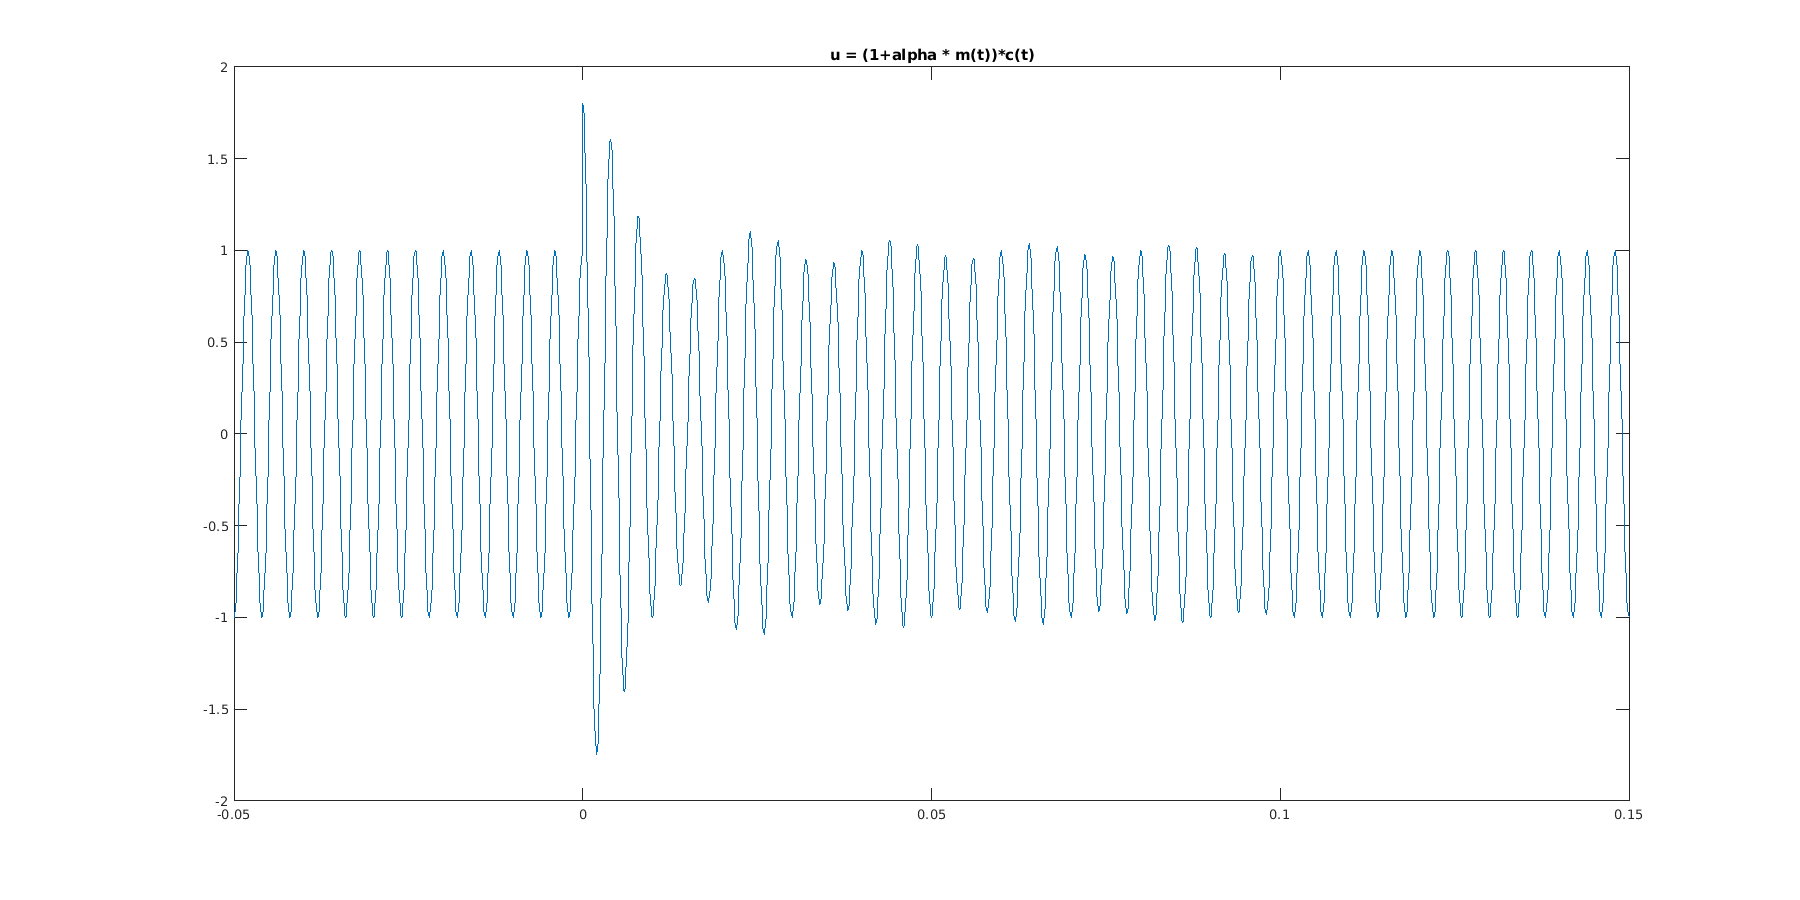


figure;
set(gcf,'position',[0,0,1800,900]);
plot(t,u(t));
title("u = (1+alpha * m(t))*c(t)")

## b

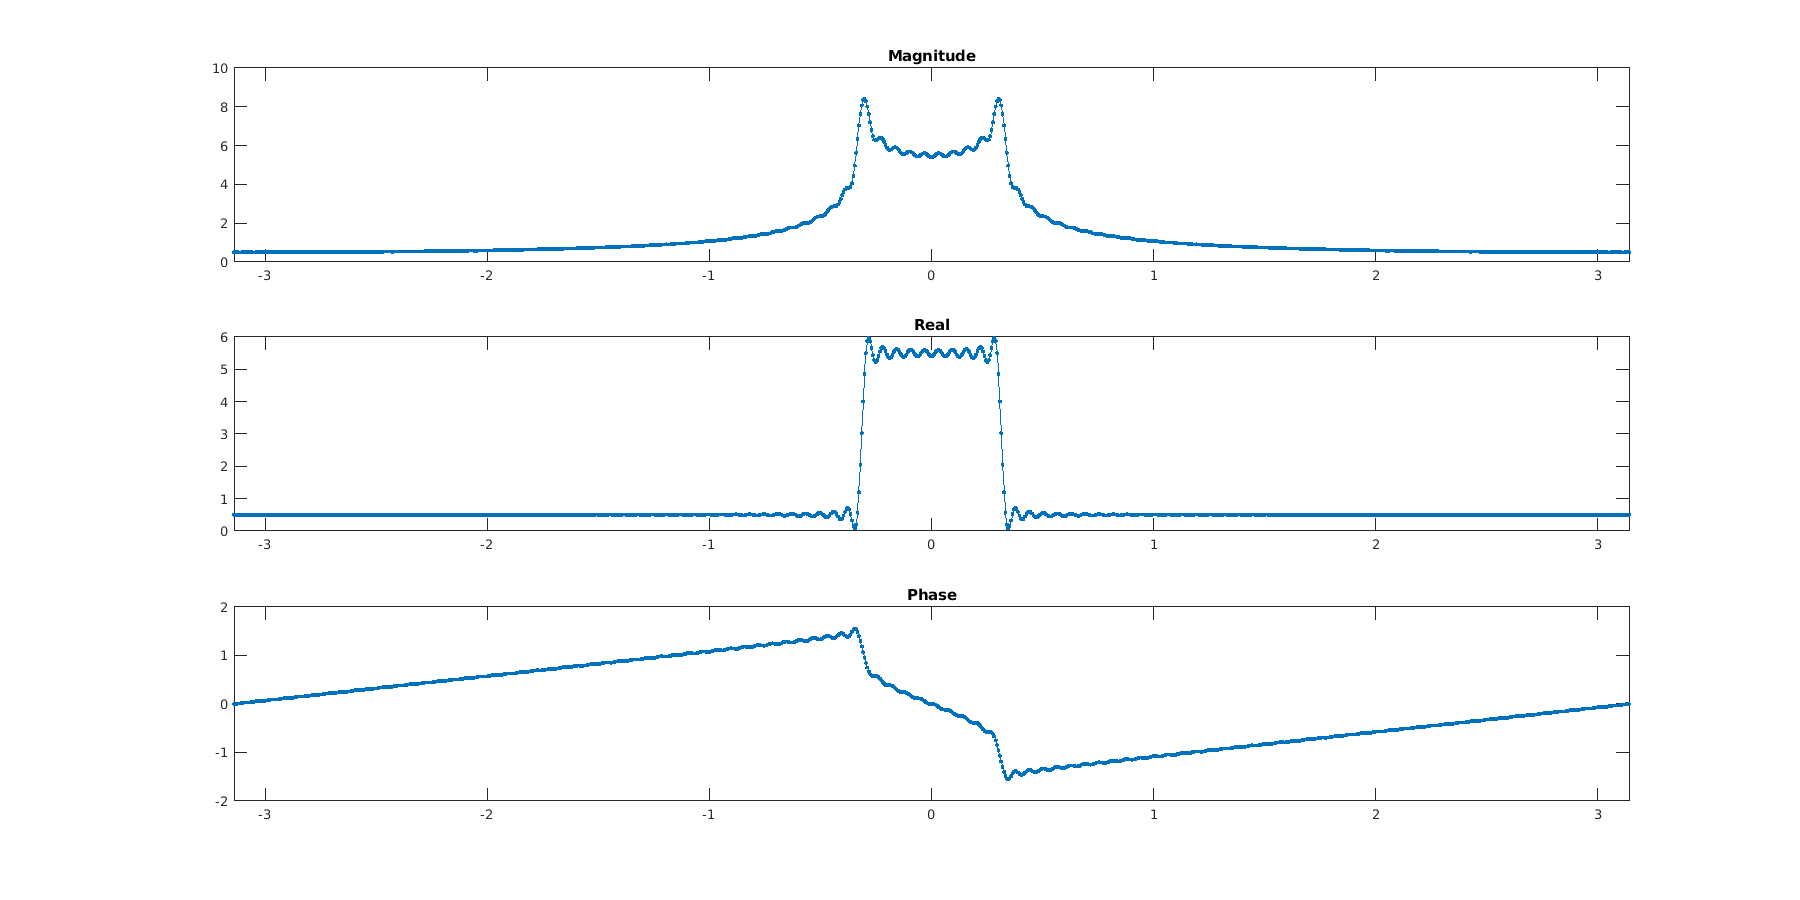

%fft_plot(fftshift(fft(m(t2))));
fft_plot(fftshift(fft(m(t2))));

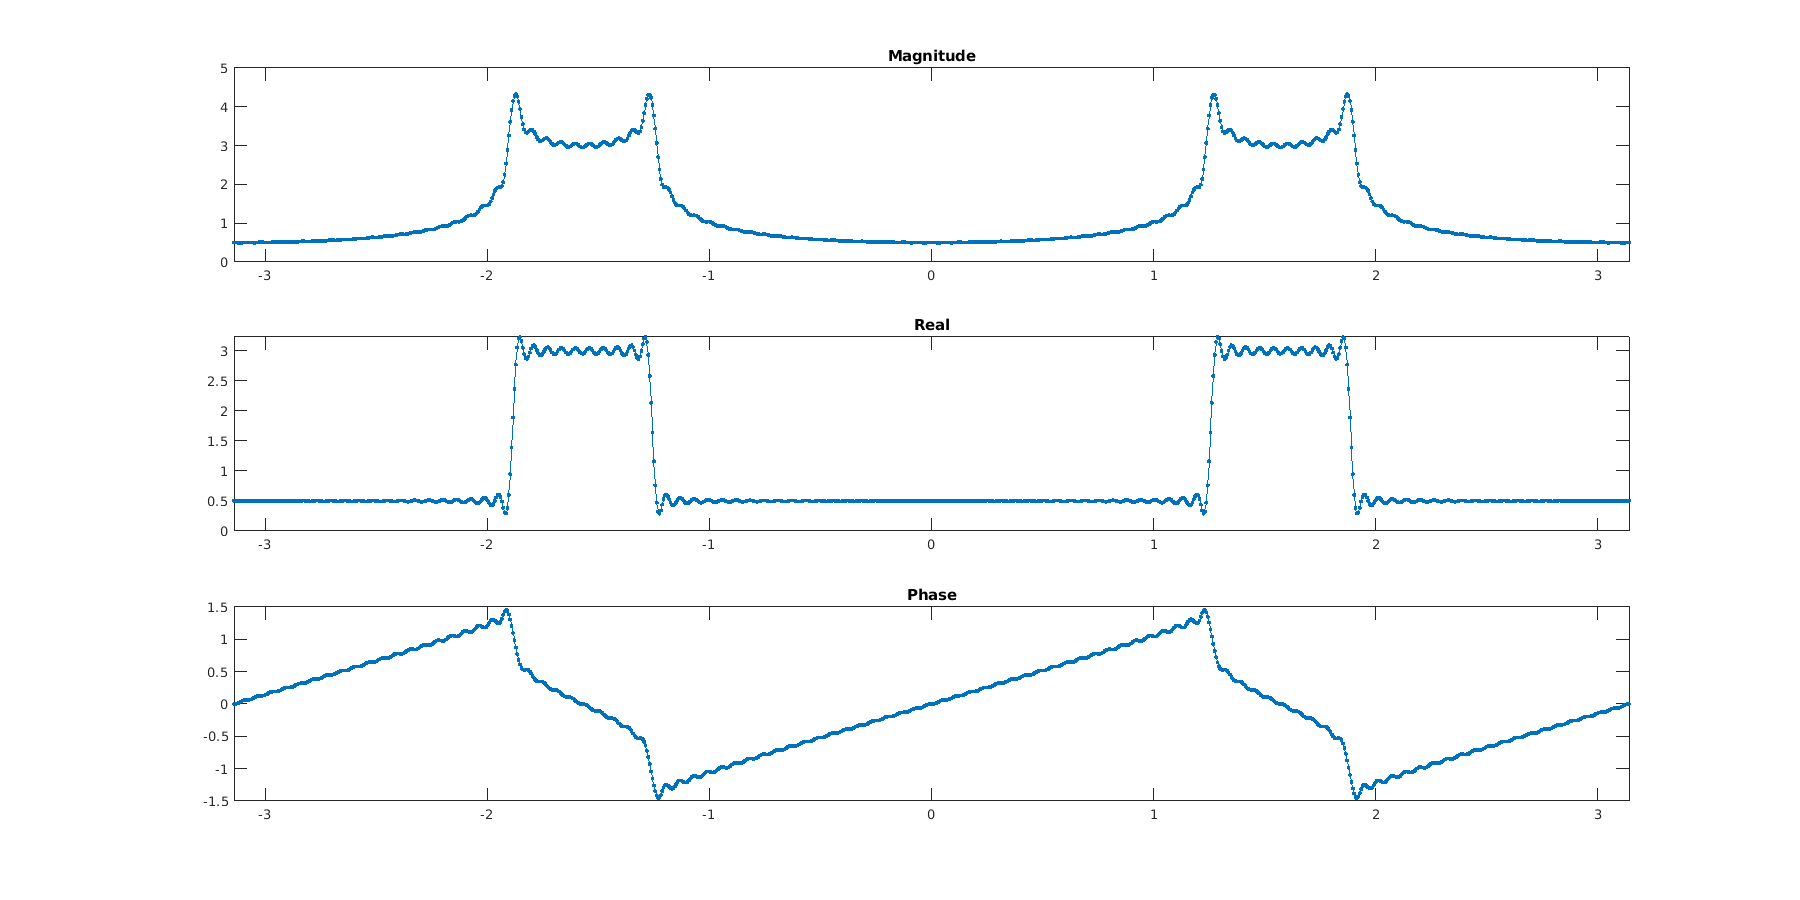

fft_plot(fftshift(fft(u2(t2))));

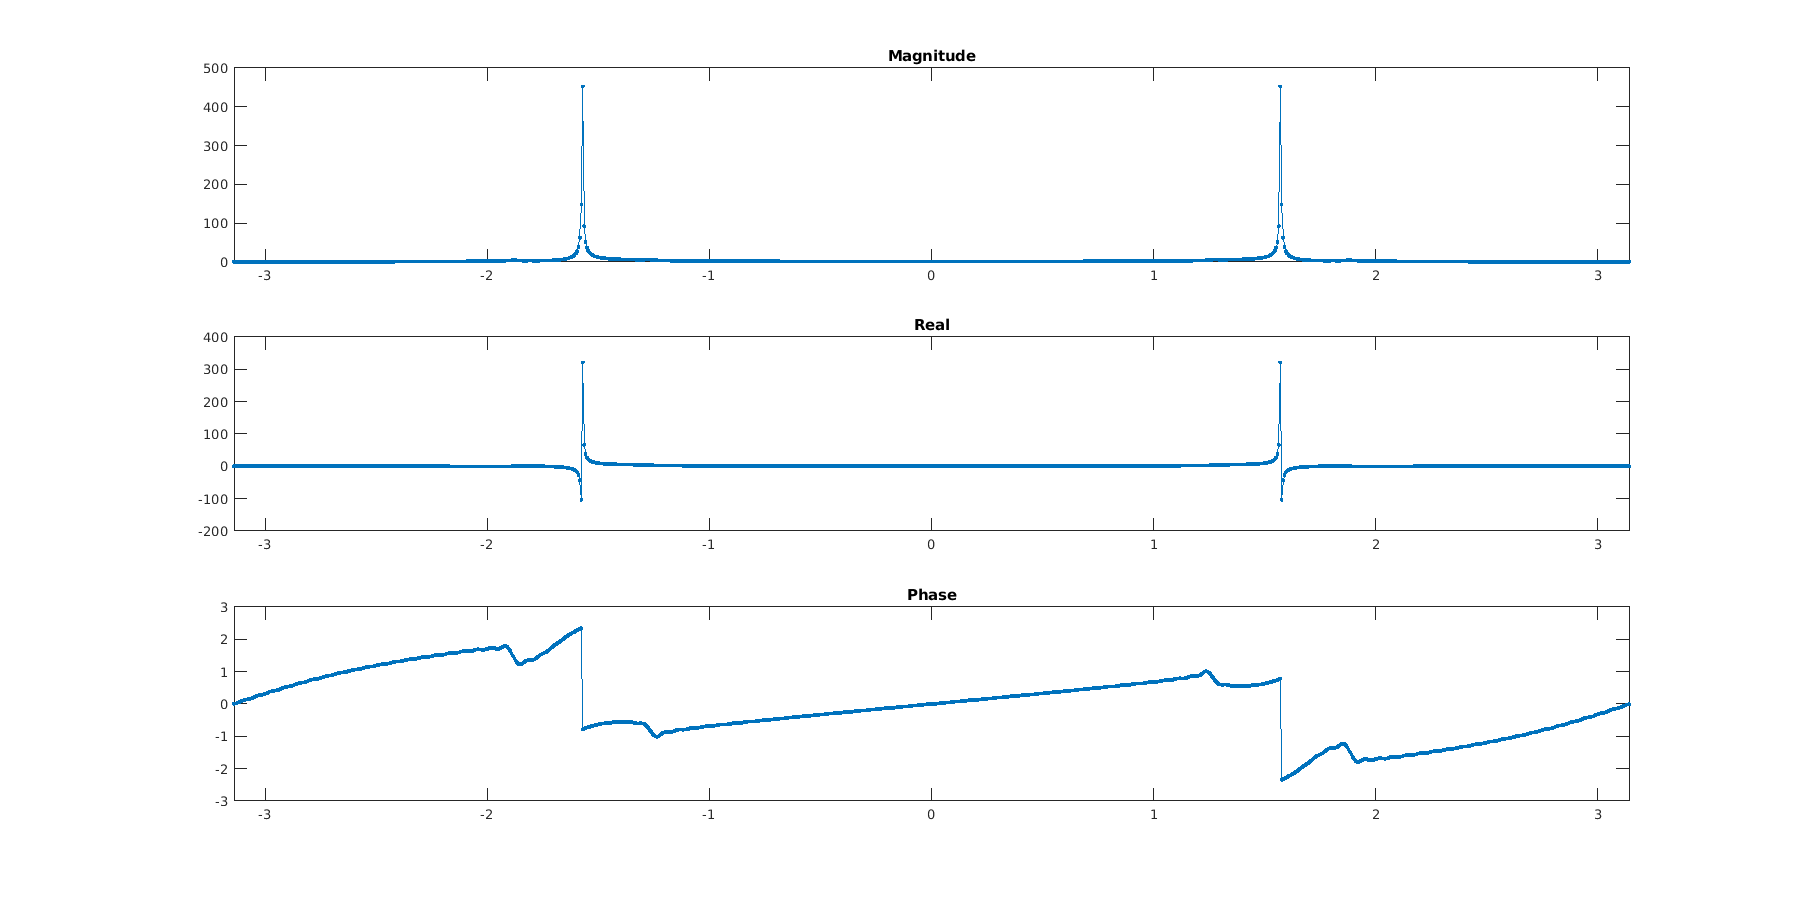

fft_plot(fftshift(fft(u(t2))));

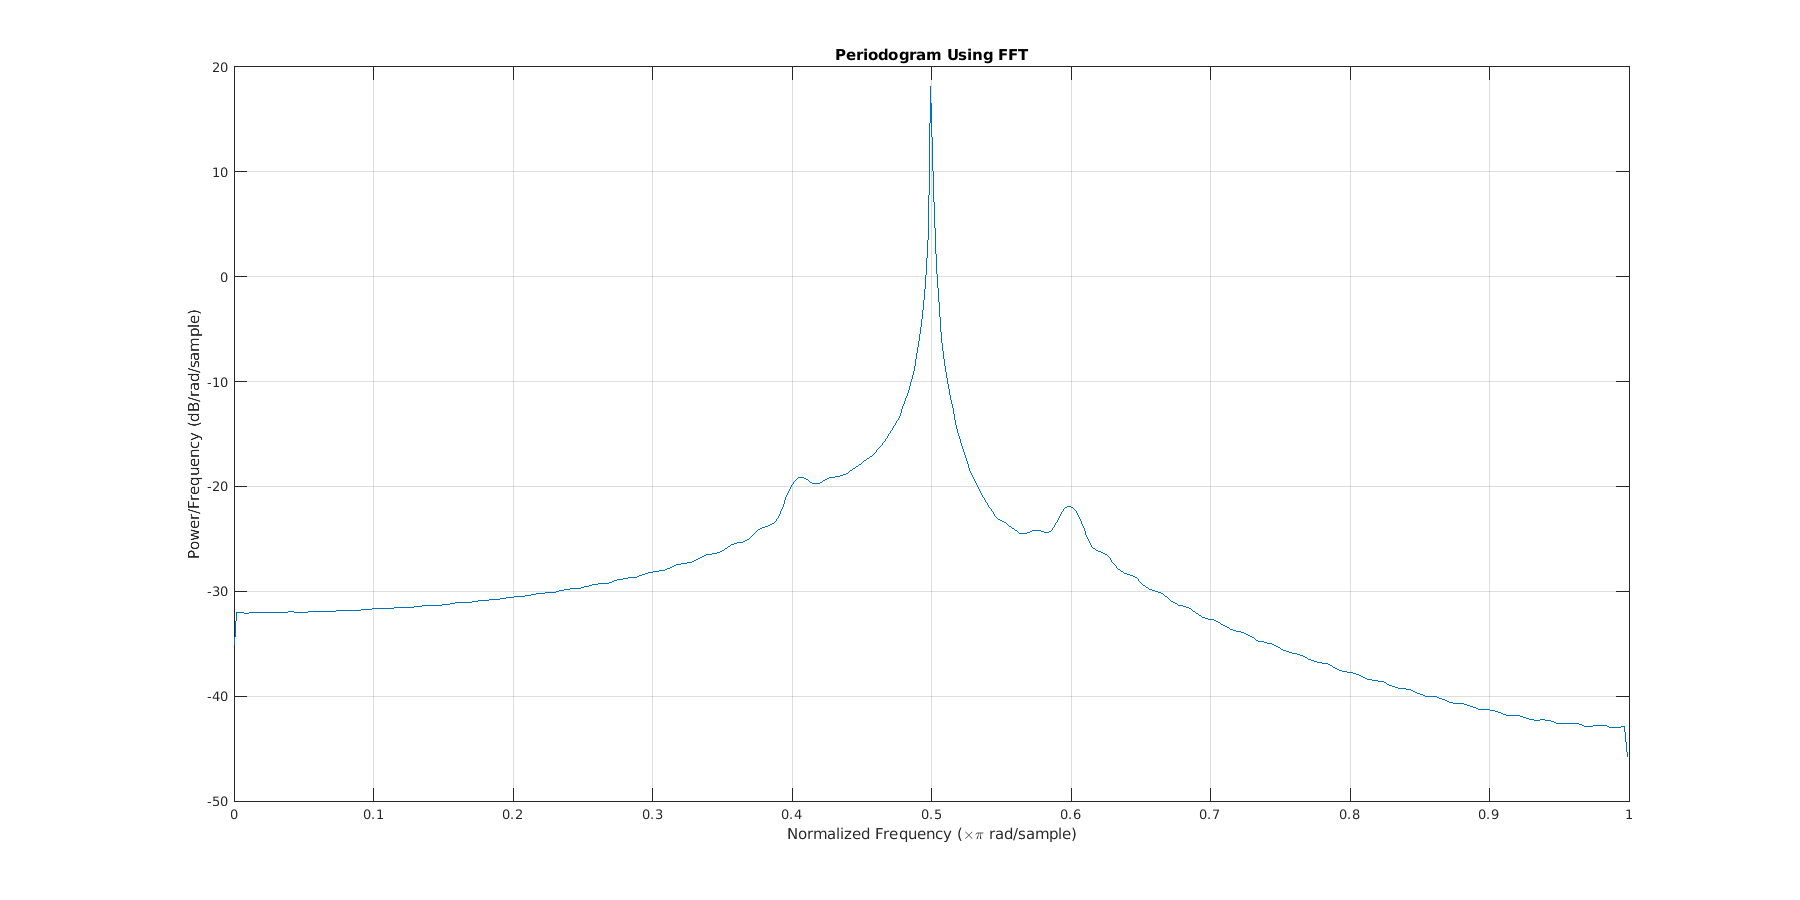

spec(u(t2))

## c

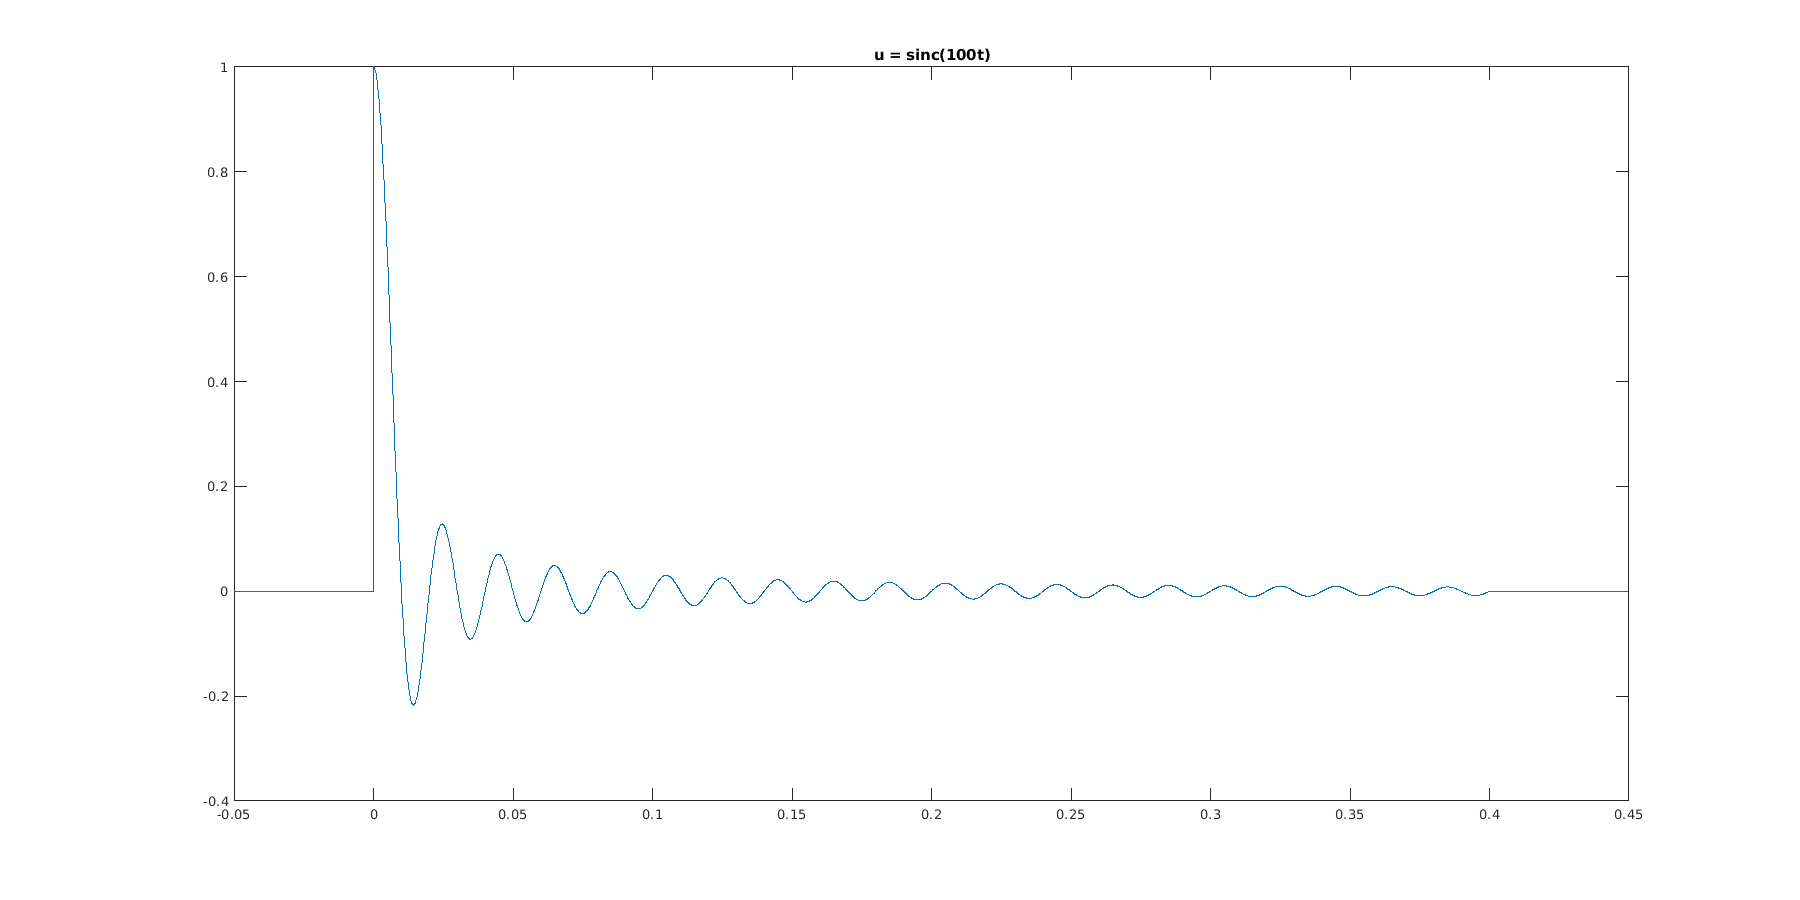

t0 = 0.4;
m = @(t) sinc(100 .* t) .* (0<=t & t <= t0);
c = @(t) cos(2*pi*fc .* t);
u = @(t) (1+ alpha * m(t)) .* c(t);
u2 = @(t) m(t) .* c(t);
t = -0.05:0.0001:t0+0.05;
t2= 0:0.001:10*t0;
%fft_plot(fftshift(fft(c(t2))));
figure;
set(gcf,'position',[0,0,1800,900]);
plot(t,m(t));
title("u = sinc(100t)")

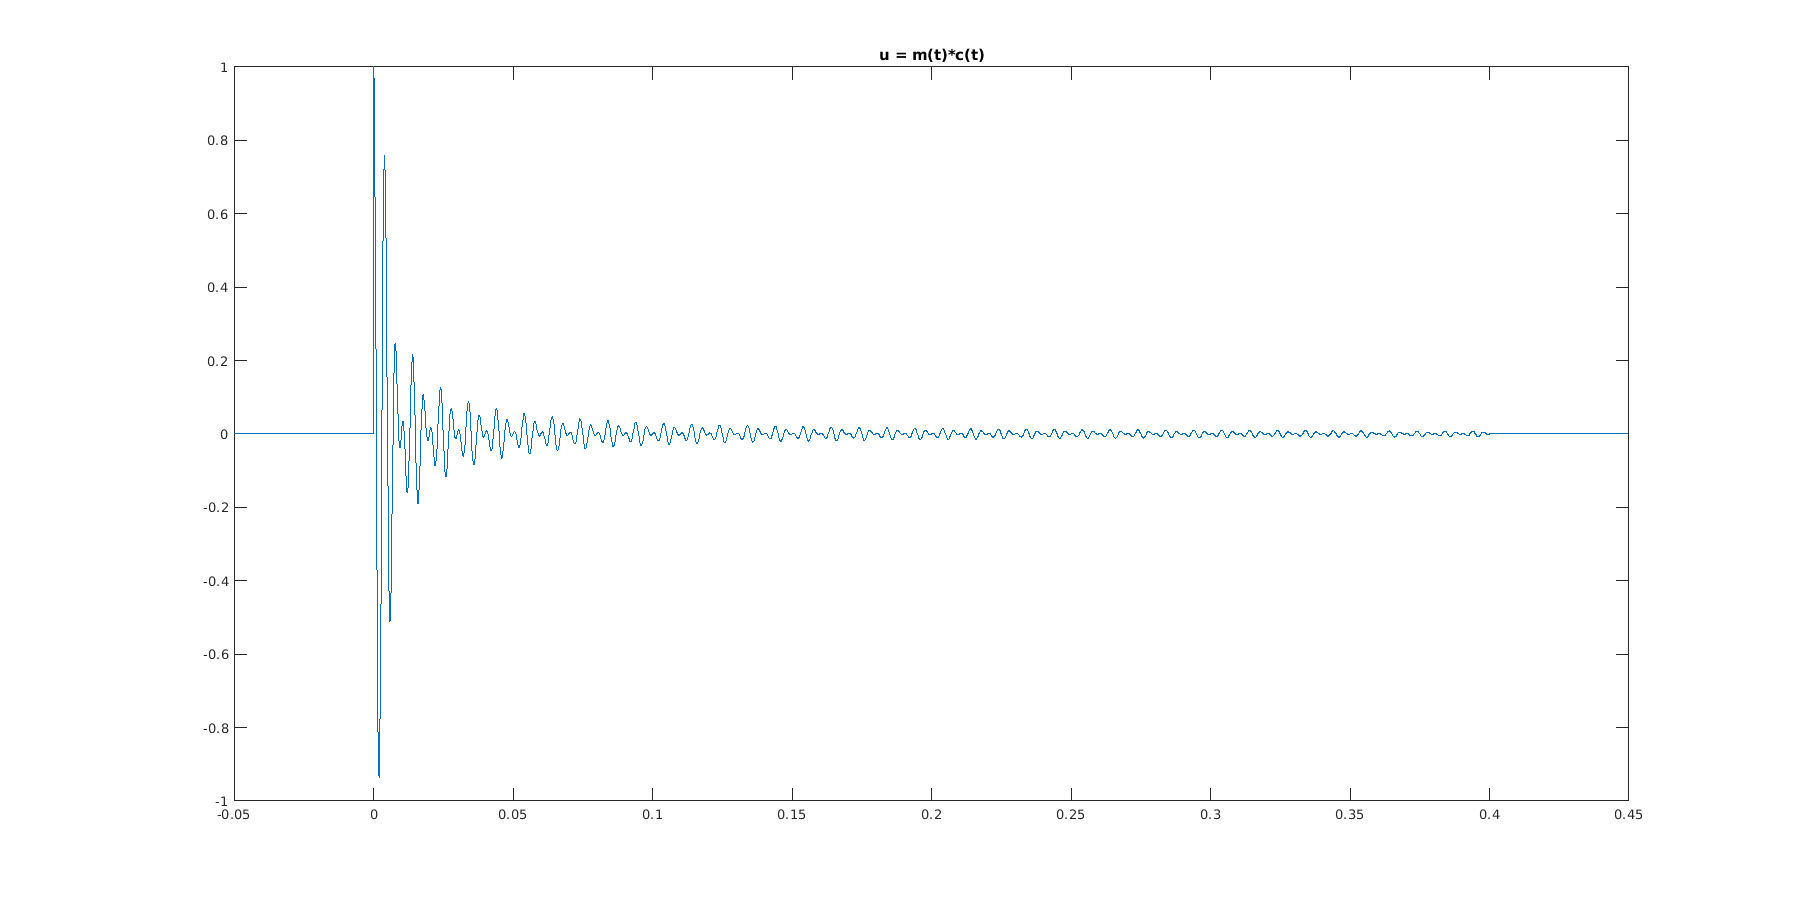

figure;
set(gcf,'position',[0,0,1800,900]);
plot(t,u2(t));
title("u = m(t)*c(t)")

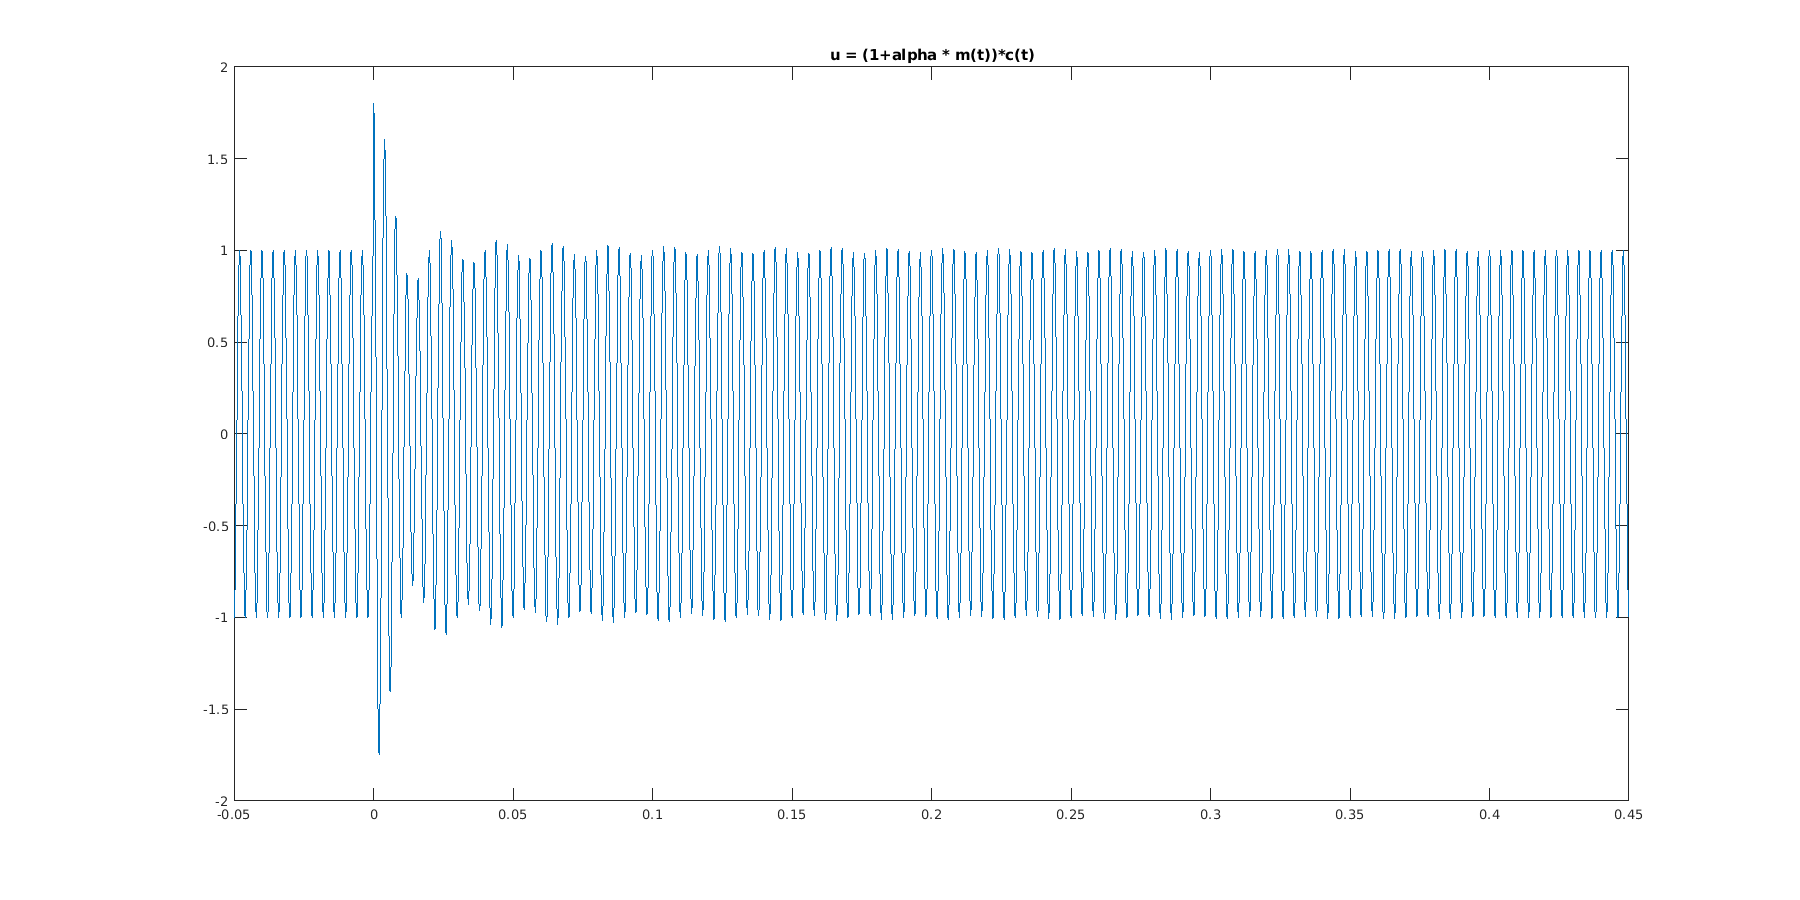

figure;
set(gcf,'position',[0,0,1800,900]);
plot(t,u(t));
title("u = (1+alpha * m(t))*c(t)")

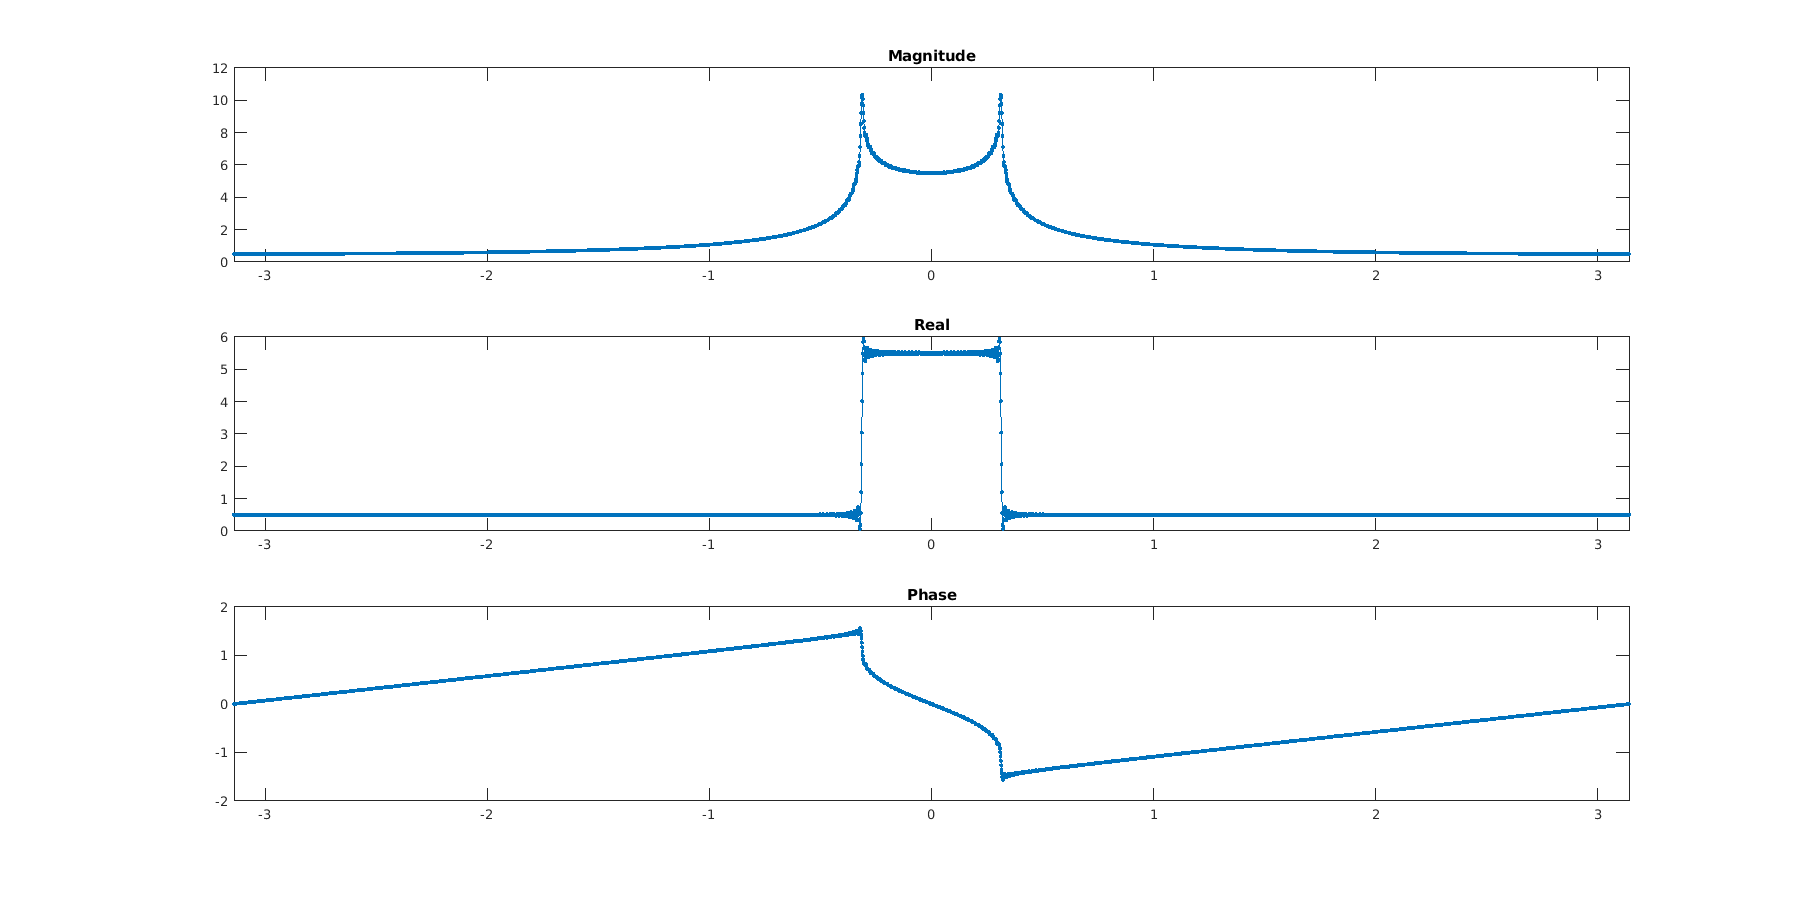

fft_plot(fftshift(fft(m(t2))));

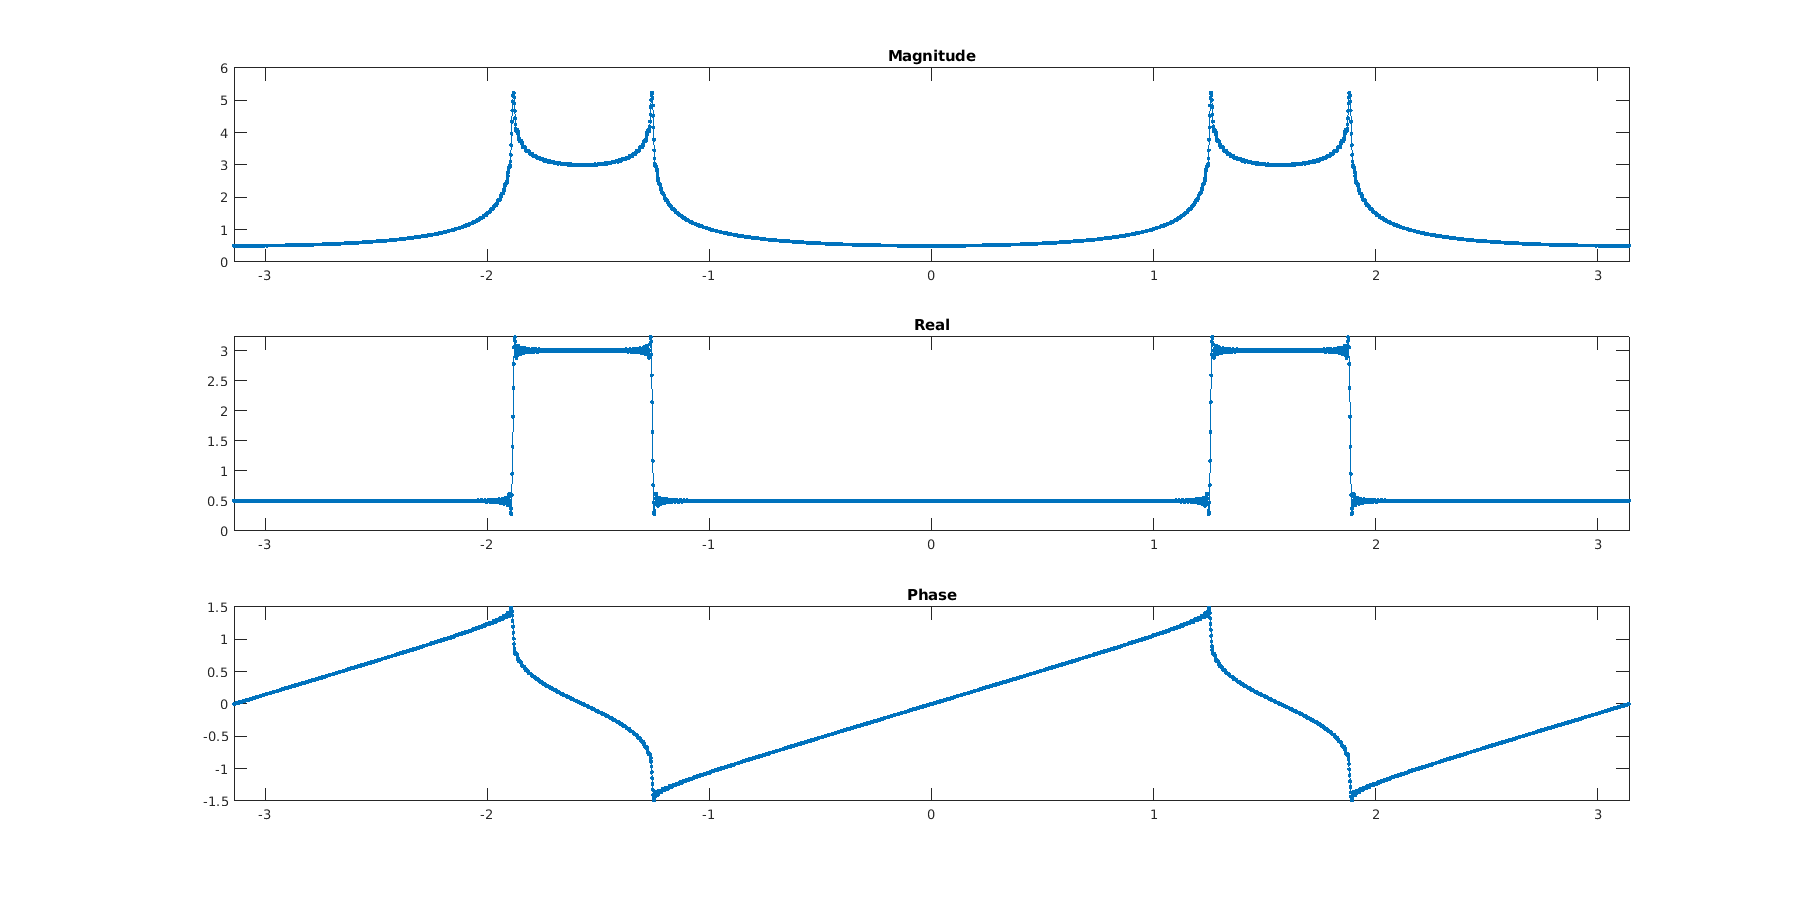

fft_plot(fftshift(fft(u2(t2))));

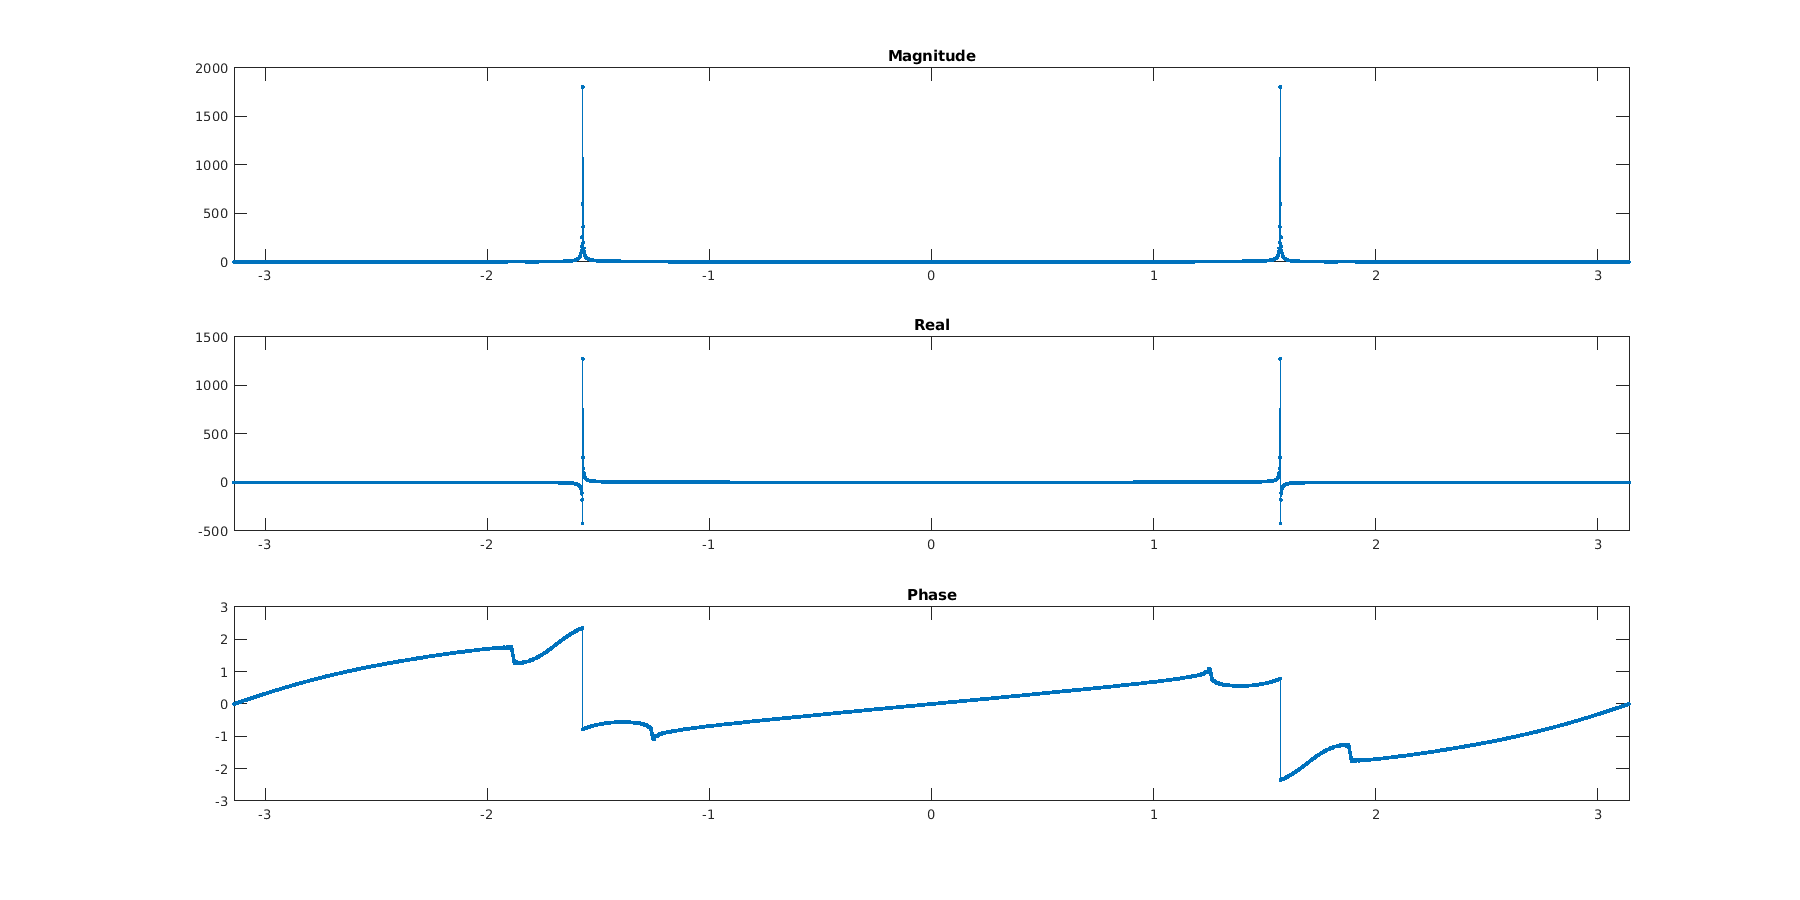

fft_plot(fftshift(fft(u(t2))));

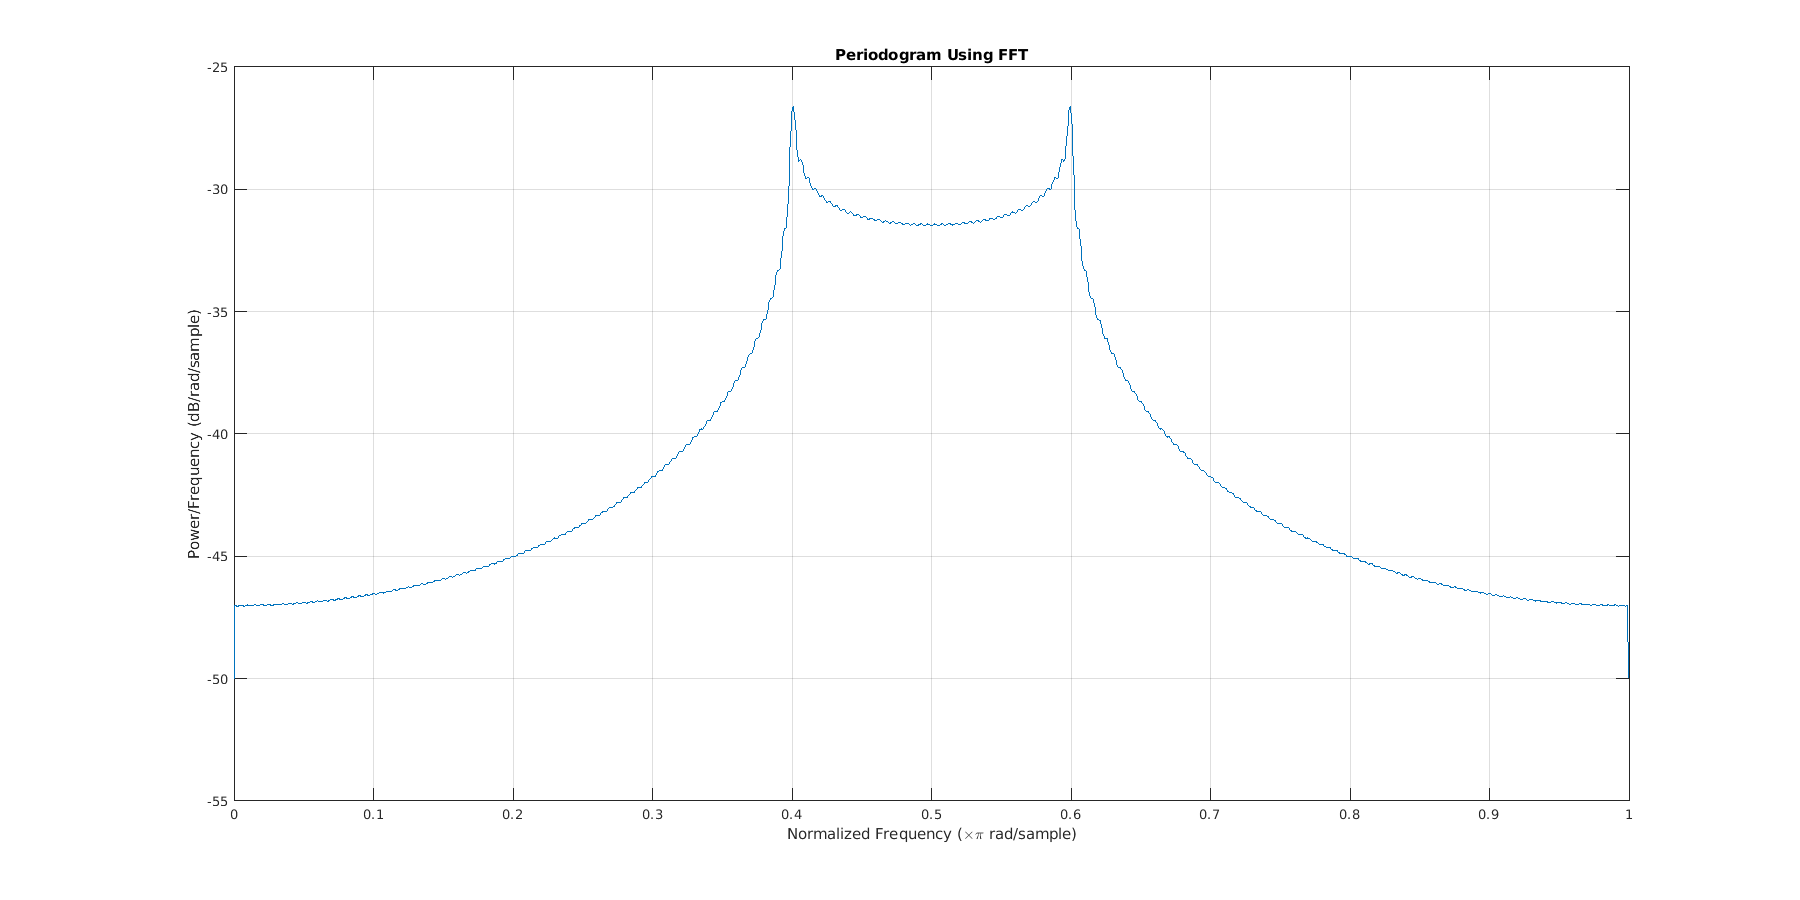

spec(u2(t2))